# Assignment 1 - Tyre fitting-

Team 6: Consalvi Natale - Pettene Mattia - Zumerle Matteo

## --Initialization

define geometric data of tyre, import the path

clc;
close all;
clear;

set(0,'defaulttextinterpreter','latex')
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(0,'DefaultFigureWindowStyle','docked');
set(0,'defaultAxesFontSize',  16)
set(0,'DefaultLegendFontSize',16)

addpath('dataset/');
addpath('tyre_lib/');

% Tyre geometric data:
diameter = 18*2.56; %
Fz0 = 220;   % [N] nominal load
R0  = diameter/2/100; % [m] get from nominal load R0 (m)

% Constants for angle conversions
to_rad = pi/180;
to_deg = 180/pi;

data_set_path = 'dataset/';

## --Initialization phase for tyre coefficients

tyre_coeffs_pl = initialise_tyre_data_ply(R0, Fz0);

SL_vec = -0.3:0.001:0.3;

## --Pure longitudinal force FX0: dataset import

last_fig_FX0 = 10;

## --Pure lateral force FY0: dataset import

data_set = 'Hoosier_B1464run23'; % pure lateral forces

fprintf('Loading dataset: ')

Loading dataset: 


switch data_set
  case 'Hoosier_B1464run23'
      fprintf('for pure lateral force analysis.')
      load ([data_set_path, data_set]); % pure lateral

  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

for pure lateral force analysis.


% select dataset portion (at the higher pressure)
%cut_start_pl = 31350;
cut_start_pl = 27760;
cut_end_pl   = 54500;


smpl_range_pl = cut_start_pl:cut_end_pl;

fprintf('\ncompleted!')


completed!

## ---Dataset for pure lateral: plot

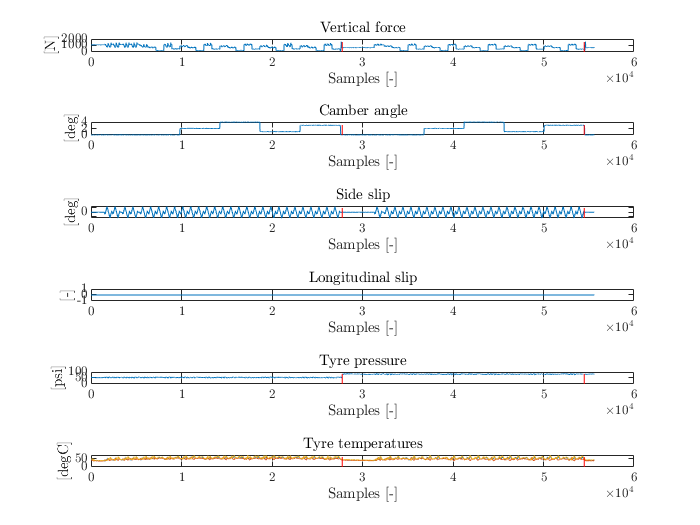

figure ('Name','FY0: entire raw dataset', 'NumberTitle', 1 + last_fig_FX0)
tiledlayout(6,1)

ax_list(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start_pl cut_start_pl],y_range,'--r')
plot([cut_end_pl cut_end_pl],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start_pl cut_start_pl],y_range,'--r')
plot([cut_end_pl cut_end_pl],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start_pl cut_start_pl],y_range,'--r')
plot([cut_end_pl cut_end_pl],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start_pl cut_start_pl],y_range,'--r')
plot([cut_end_pl cut_end_pl],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start_pl cut_start_pl],y_range,'--r')
plot([cut_end_pl cut_end_pl],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[psi]')

ax_list(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start_pl cut_start_pl],y_range,'--r')
plot([cut_end_pl cut_end_pl],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list,'x')

## ---Higher pressure dataset for pure lateral force: table selection and plot

consider the high pressure region of original dataset (more stable one)

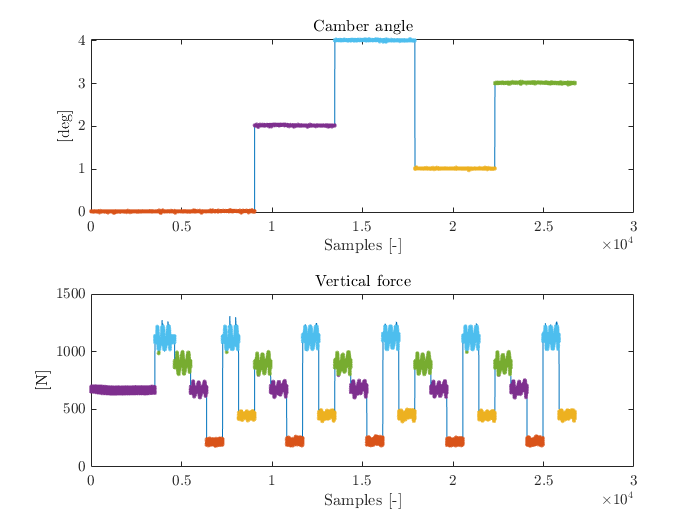

vec_samples_pl = 1:1:length(smpl_range_pl);

tyre_data_pl = table();
% store raw data in table
tyre_data_pl.SL =  SL(smpl_range_pl);
tyre_data_pl.SA = -SA(smpl_range_pl)*to_rad;    % SAE -> Adapted SAE
tyre_data_pl.FZ = -FZ(smpl_range_pl);           % SAE -> Adapted SAE
tyre_data_pl.FX =  FX(smpl_range_pl);
tyre_data_pl.FY =  FY(smpl_range_pl);   
tyre_data_pl.MZ =  MZ(smpl_range_pl);
tyre_data_pl.IA =  IA(smpl_range_pl)*to_rad;

% Extract points at constant camber angle

% Test data done at: 
%  - 0 deg
%  - 1 deg
%  - 2 deg
%  - 3 deg
%  - 4 deg
% in the following order: (0 2 4 1 3)*2

GAMMA_tol_pl = 0.05*to_rad;
idx_pl.GAMMA_0 = 0.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 0.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_1 = 1.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 1.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_2 = 2.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 2.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_3 = 3.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 3.0*to_rad+GAMMA_tol_pl;
idx_pl.GAMMA_4 = 4.0*to_rad-GAMMA_tol_pl < tyre_data_pl.IA & tyre_data_pl.IA < 4.0*to_rad+GAMMA_tol_pl;

GAMMA_0_pl  = tyre_data_pl( idx_pl.GAMMA_0, : );
GAMMA_1_pl  = tyre_data_pl( idx_pl.GAMMA_1, : );
GAMMA_2_pl  = tyre_data_pl( idx_pl.GAMMA_2, : );
GAMMA_3_pl  = tyre_data_pl( idx_pl.GAMMA_3, : );
GAMMA_4_pl  = tyre_data_pl( idx_pl.GAMMA_4, : );

% Extract points at constant vertical load

% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 100lbf (100*0.453592*9.81 =  445N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )
% in the following order: (200 150 50 250 100)*2

FZ_tol_pl = 100;
idx_pl.FZ_220  = 220-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 220+FZ_tol_pl;
idx_pl.FZ_440  = 440-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 440+FZ_tol_pl;
idx_pl.FZ_700  = 700-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 700+FZ_tol_pl;
idx_pl.FZ_900  = 900-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 900+FZ_tol_pl;
idx_pl.FZ_1120 = 1120-FZ_tol_pl < tyre_data_pl.FZ & tyre_data_pl.FZ < 1120+FZ_tol_pl;
FZ_220_pl  = tyre_data_pl( idx_pl.FZ_220, : );
FZ_440_pl  = tyre_data_pl( idx_pl.FZ_440, : );
FZ_700_pl  = tyre_data_pl( idx_pl.FZ_700, : );
FZ_900_pl  = tyre_data_pl( idx_pl.FZ_900, : );
FZ_1120_pl = tyre_data_pl( idx_pl.FZ_1120, : );

% Plot
figure('Name','FY0: higher pressure dataset with regions', 'NumberTitle', 2 + last_fig_FX0)
tiledlayout(2,1)

ax_list_2(1) = nexttile;
plot(tyre_data_pl.IA*to_deg)
hold on
plot(vec_samples_pl(idx_pl.GAMMA_0),GAMMA_0_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_1),GAMMA_1_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_2),GAMMA_2_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_3),GAMMA_3_pl.IA*to_deg,'.');
plot(vec_samples_pl(idx_pl.GAMMA_4),GAMMA_4_pl.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_2(2) = nexttile;
plot(tyre_data_pl.FZ)
hold on
plot(vec_samples_pl(idx_pl.FZ_220),FZ_220_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_440),FZ_440_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_700),FZ_700_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_900),FZ_900_pl.FZ,'.');
plot(vec_samples_pl(idx_pl.FZ_1120),FZ_1120_pl.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')
hold off
linkaxes(ax_list_2,'x')

## ---FY0: fitting in pure conditions (gamma = 0, Fz = 220N)

choose the range with: longitudinal slip = 0, camber angle = 0, vertical load = Fz = 220N (obv within the higher pressure dataset)

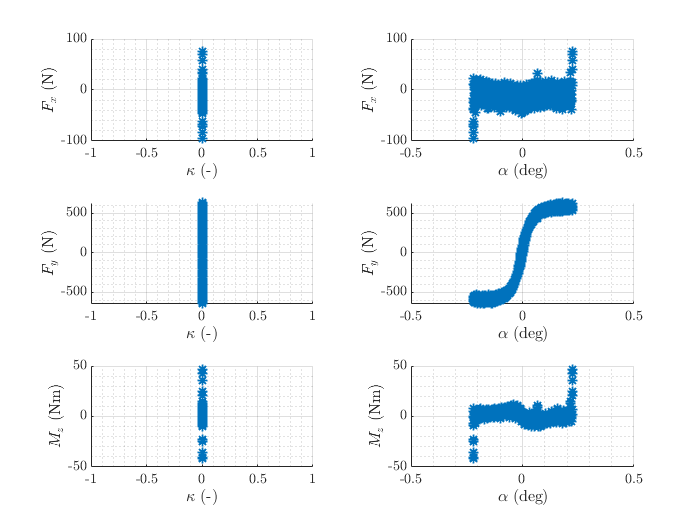

[TData0_pl, ~] = intersect_table_data( GAMMA_0_pl, FZ_220_pl );

figure('Name','FY0: pure conditions range', 'NumberTitle', 3 + last_fig_FX0)
plot_selected_data(TData0_pl);

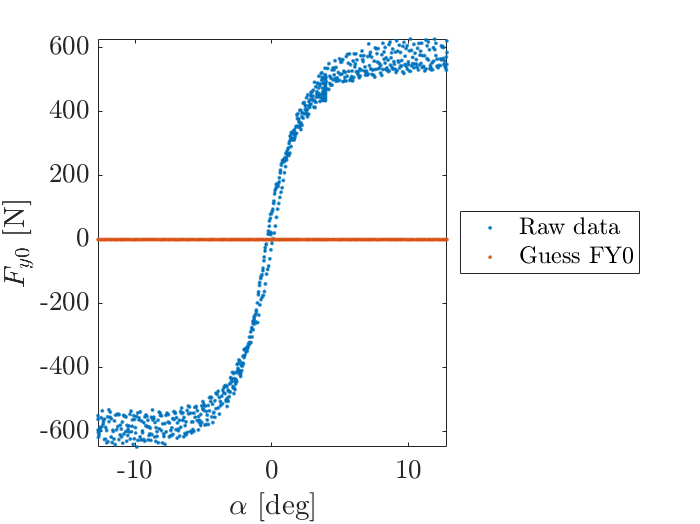


% Fit the coefficients {pCy1, pDy1, pEy1, pHy1, pKy1, pKy2, pVy1}

zeros_vec_pl = zeros(size(TData0_pl.SA));
ones_vec_pl  = ones(size(TData0_pl.SA));

% Initial guess (import from initialization of tyre_coeffs)
[FY0_guess,~] = MF96_FY0_vec(zeros_vec_pl, TData0_pl.SA , zeros_vec_pl, tyre_coeffs_pl.FZ0*ones_vec_pl, tyre_coeffs_pl);

% Check lateral pure force guess
figure('Name','FY0: guess', 'NumberTitle', 4 + last_fig_FX0)
plot(TData0_pl.SA*to_deg,TData0_pl.FY,'.')
hold on
plot(TData0_pl.SA*to_deg,FY0_guess,'.')
hold off
legend({'Raw data','Guess FY0'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}$ [N]')


% Guess values for parameters to be optimised
%       [pCy1 pDy1 pEy1 pHy1  pKy1  pKy2  pVy1]
P0_FY0_pure = [1.3, 2.7, -1, 0.0038, 170, 5.05, -0.0792];


% Limits for parameters to be optimised
%        [pCy1 pDy1 pEy1 pHy1  pKy1  pKy2  pVy1]
lb_FY0_pure = [ 1.1, 2.5, -1000, -1000,0, 4.9, -1000];
ub_FY0_pure = [ 1000, 1000, 1, 1000, 175, 5.1, 1000];


ALPHA_vec = TData0_pl.SA;
FY_vec    = TData0_pl.FY;

% Vector for plotting: Side slip vector from -12.5° to 12.5°
SA_vec = (-12.5*to_rad):0.001:(12.5*to_rad);

% Minimization of the residual
[P_opt_FY0_pure,fval_FY0_pure,exitflag_FY0_pure] = fmincon(@(P)resid_pure_Fy(P,FY_vec, ALPHA_vec,0,mean(TData0_pl.FZ), tyre_coeffs_pl),...
                               P0_FY0_pure,[],[],[],[],lb_FY0_pure,ub_FY0_pure);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


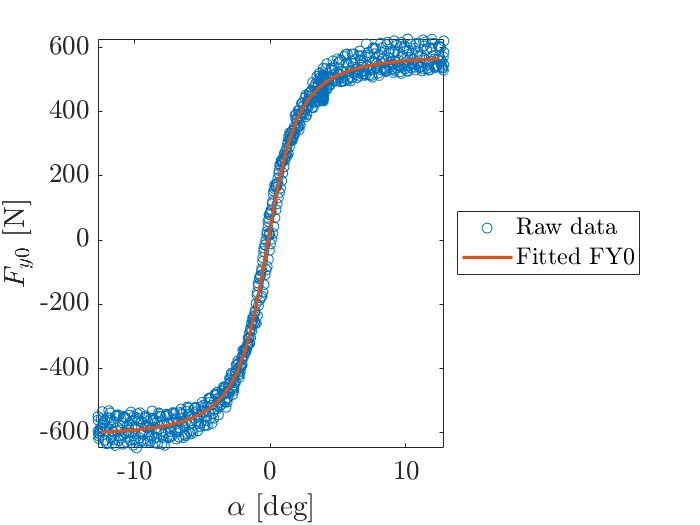


% Update tyre data with new optimal values                            
tyre_coeffs_pl.pCy1 = P_opt_FY0_pure(1) ;
tyre_coeffs_pl.pDy1 = P_opt_FY0_pure(2) ;  
tyre_coeffs_pl.pEy1 = P_opt_FY0_pure(3) ;
tyre_coeffs_pl.pHy1 = P_opt_FY0_pure(4) ;
tyre_coeffs_pl.pKy1 = P_opt_FY0_pure(5) ; 
tyre_coeffs_pl.pKy2 = P_opt_FY0_pure(6) ;
tyre_coeffs_pl.pVy1 = P_opt_FY0_pure(7) ;

res_FY0 = resid_pure_Fy(P_opt_FY0_pure , FY_vec, SA_vec, 0 , mean(TData0_pl.FZ), tyre_coeffs_pl);


% Plot of the optimized solution
[FY0_fz_nom_vec,~] = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec , zeros(size(SA_vec)), ...
                              mean(TData0_pl.FZ).*ones(size(SA_vec)),tyre_coeffs_pl);

% Result of the fitting FY0 in the pure conditions
figure('Name','FY0: fitted in pure conditions','NumberTitle', 5 + last_fig_FX0)
plot(TData0_pl.SA*to_deg,TData0_pl.FY,'o')
hold on
plot(SA_vec*to_deg,FY0_fz_nom_vec,'-','LineWidth',2)
legend({'Raw data','Fitted FY0'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}$ [N]')

## ---FY0(Fz): fitting with variable Fz

extract data with variable load and camber angle equal to 0

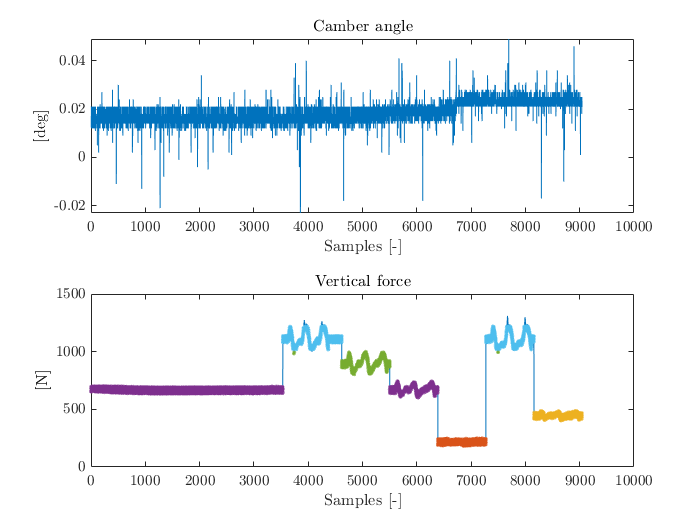

TDataDFz_pl = GAMMA_0_pl;

% figure('Name','Variable Fz range', 'NumberTitle', 6 + last_fig_FX0)
% plot_selected_data(TDataDFz);

smpl_range_pl_dFz = size(TDataDFz_pl);
vec_samples_pl_dFz = 1:1:smpl_range_pl_dFz;

% Extract points at constant vertical load
FZ_tol_pl_dFz = 100;
idx_pl_dFz.FZ_220  = 220-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 220+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_440  = 440-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 440+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_700  = 700-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 700+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_900  = 900-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 900+FZ_tol_pl_dFz;
idx_pl_dFz.FZ_1120 = 1120-FZ_tol_pl_dFz < TDataDFz_pl.FZ & TDataDFz_pl.FZ < 1120+FZ_tol_pl_dFz;
FZ_220_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_220, : );
FZ_440_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_440, : );
FZ_700_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_700, : );
FZ_900_pl_dFz  = TDataDFz_pl( idx_pl_dFz.FZ_900, : );
FZ_1120_pl_dFz = TDataDFz_pl( idx_pl_dFz.FZ_1120, : );

% Plot
figure('Name','FY0(Fz): considered dataset', 'NumberTitle', 6 + last_fig_FX0)
tiledlayout(2,1)

ax_list_3(1) = nexttile;
plot(TDataDFz_pl.IA*to_deg)
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_3(2) = nexttile;
plot(TDataDFz_pl.FZ)
hold on
plot(vec_samples_pl_dFz(idx_pl_dFz.FZ_220),FZ_220_pl_dFz.FZ,'.');
plot(vec_samples_pl_dFz(idx_pl_dFz.FZ_440),FZ_440_pl_dFz.FZ,'.');
plot(vec_samples_pl_dFz(idx_pl_dFz.FZ_700),FZ_700_pl_dFz.FZ,'.');
plot(vec_samples_pl_dFz(idx_pl_dFz.FZ_900),FZ_900_pl_dFz.FZ,'.');
plot(vec_samples_pl_dFz(idx_pl_dFz.FZ_1120),FZ_1120_pl_dFz.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')
hold off
linkaxes(ax_list_3,'x')

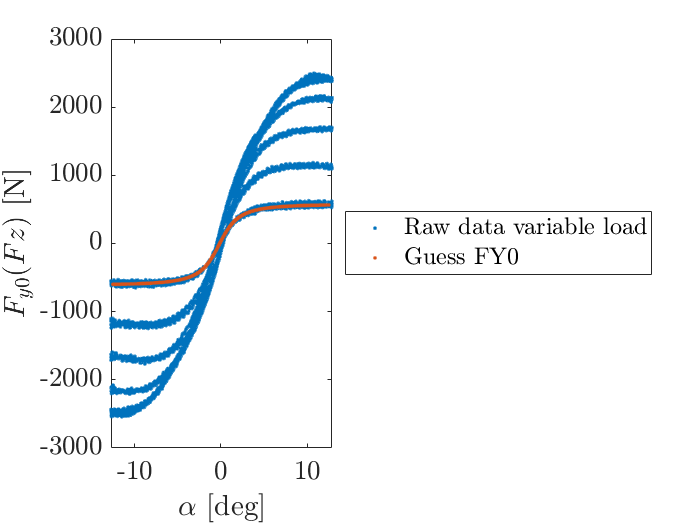


zeros_vec_pl = zeros(size(TDataDFz_pl.SA));
ones_vec_pl  = ones(size(TDataDFz_pl.SA));

% Guess values for parameters to be optimised
%    [pDy2 pEy2 pHy2 pVy2] 
P0_FY0_dFz =[ -0.05, -1, 0, 0 ]; 


% Limits for parameters to be optimised
%    [pDy2 pEy2 pHy2 pVy2] 
lb_FY0_dFz = [ -0.2, -100, -100, -100];
ub_FY0_dFz = [ 0, 100, 100, 100];

ALPHA_vec_dFz = TDataDFz_pl.SA;
FY_vec_dFz    = TDataDFz_pl.FY;
FZ_vec_dFz    = TDataDFz_pl.FZ;

% check guess for variable load
[FY0_dfz_vec,~] = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec, zeros(size(SA_vec)), ...
                              mean(FZ_220_pl_dFz.FZ)*ones(size(SA_vec)),tyre_coeffs_pl);

figure('Name','FY0(Fz): guess', 'NumberTitle', 7 + last_fig_FX0)
plot(ALPHA_vec_dFz*to_deg,FY_vec_dFz,'.')
hold on
plot(SA_vec*to_deg,FY0_dfz_vec,'.')
legend({'Raw data variable load','Guess FY0'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}(Fz)$ [N]')


% Resitual minimization
[P_opt_FY0_dFz,fval_FY0_dFz,exitflag_FY0_dFz] = fmincon(@(P_pl)resid_pure_Fy_varFz(P_pl,FY_vec_dFz, ALPHA_vec_dFz,0,FZ_vec_dFz, tyre_coeffs_pl),...
                               P0_FY0_dFz,[],[],[],[],lb_FY0_dFz,ub_FY0_dFz);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


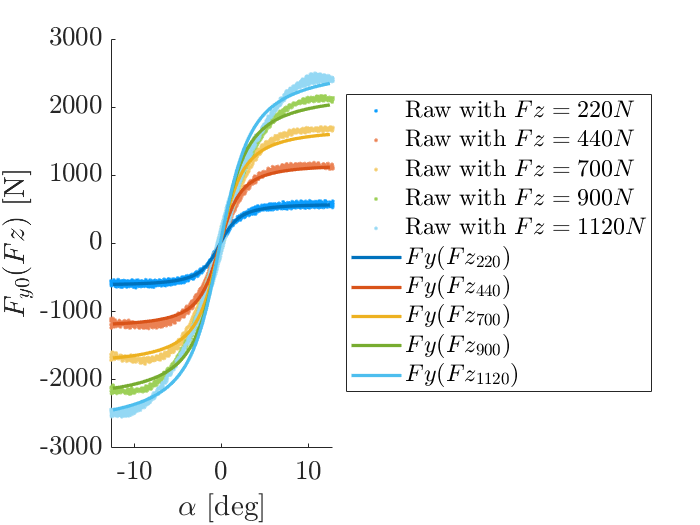


% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDy2 = P_opt_FY0_dFz(1);
tyre_coeffs_pl.pEy2 = P_opt_FY0_dFz(2);
tyre_coeffs_pl.pHy2 = P_opt_FY0_dFz(3);
tyre_coeffs_pl.pVy2 = P_opt_FY0_dFz(4);

res_FY0_dfz = resid_pure_Fy_varFz(P_opt_FY0_dFz , FY_vec_dFz,SA_vec, 0 , FZ_vec_dFz, tyre_coeffs_pl);

tmp_zeros_dFz = zeros(size(SA_vec));
tmp_ones_dFz = ones(size(SA_vec));

[FY0_fz_var_vec1, ~] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_220_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec2, ~] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_440_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec3, ~] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_700_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec4, ~] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_900_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
[FY0_fz_var_vec5, ~] = MF96_FY0_vec(tmp_zeros_dFz, SA_vec ,tmp_zeros_dFz, mean(FZ_1120_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);


figure('Name','FY0(Fz): fitted with variable Fz','NumberTitle', 8 + last_fig_FX0)
hold on
plot(FZ_220_pl_dFz.SA*to_deg,FZ_220_pl_dFz.FY,'.', 'Color', '#0b9eff')
plot(FZ_440_pl_dFz.SA*to_deg,FZ_440_pl_dFz.FY,'.', 'Color', '#eb8153')
plot(FZ_700_pl_dFz.SA*to_deg,FZ_700_pl_dFz.FY,'.', 'Color', '#f3ca67')
plot(FZ_900_pl_dFz.SA*to_deg,FZ_900_pl_dFz.FY,'.', 'Color', '#9dd058')
plot(FZ_1120_pl_dFz.SA*to_deg,FZ_1120_pl_dFz.FY,'.', 'Color', '#94D8F4')
plot(SA_vec*to_deg,FY0_fz_var_vec1,'-','LineWidth',2, 'Color', '#0072BD')
plot(SA_vec*to_deg,FY0_fz_var_vec2,'-','LineWidth',2, 'Color', '#D95319')
plot(SA_vec*to_deg,FY0_fz_var_vec3,'-','LineWidth',2, 'Color', '#EDB120')
plot(SA_vec*to_deg,FY0_fz_var_vec4,'-','LineWidth',2, 'Color', '#77AC30')
plot(SA_vec*to_deg,FY0_fz_var_vec5,'-','LineWidth',2, 'Color', '#4DBEEE')
legend({'Raw with $Fz=220N$','Raw with $Fz=440N$','Raw with $Fz=700N$','Raw with $Fz=900N$','Raw with $Fz=1120N$', '$Fy(Fz_{220})$','$Fy(Fz_{440})$','$Fy(Fz_{700})$','$Fy(Fz_{900})$','$Fy(Fz_{1120})$'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}(Fz)$ [N]')

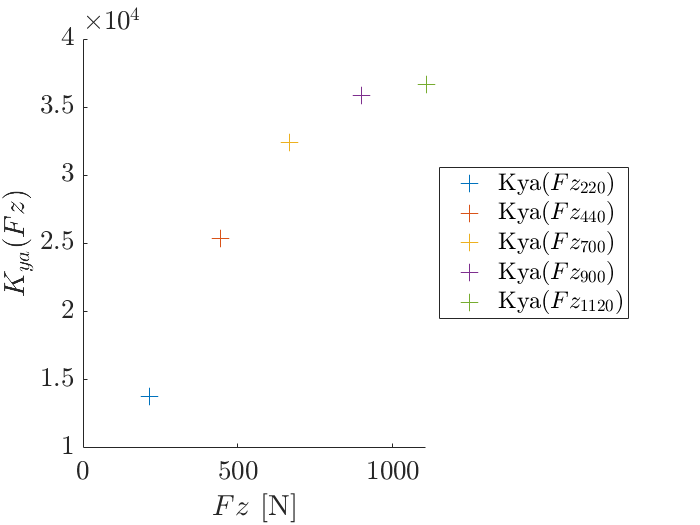



% Stiffness

[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_220_pl_dFz.FZ), tyre_coeffs_pl);
Calfa_vec1_0_y = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_440_pl_dFz.FZ), tyre_coeffs_pl);
Calfa_vec2_0_y = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_700_pl_dFz.FZ), tyre_coeffs_pl);
Calfa_vec3_0_y = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_900_pl_dFz.FZ), tyre_coeffs_pl);
Calfa_vec4_0_y = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);
[alpha__y, By, Cy, Dy, Ey, SVy, ~, ~, ~] =MF96_FY0_coeffs(0, 0, 0, mean(FZ_1120_pl_dFz.FZ), tyre_coeffs_pl);
Calfa_vec5_0_y = magic_formula_stiffness(alpha__y, By, Cy, Dy, Ey, SVy);

Calfa_vec1_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_220_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec2_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_440_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec3_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_700_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec4_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_900_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);
Calfa_vec5_y = MF96_CorneringStiffness_y(tmp_zeros_dFz,SA_vec ,tmp_zeros_dFz, mean(FZ_1120_pl_dFz.FZ)*tmp_ones_dFz,tyre_coeffs_pl);


figure('Name','Kya(Fz): cornering stiffness as function of Fz','NumberTitle', 9 + last_fig_FX0)
hold on
plot(mean(FZ_220_pl_dFz.FZ),Calfa_vec1_0_y,'+','MarkerSize',10)
plot(mean(FZ_440_pl_dFz.FZ),Calfa_vec2_0_y,'+','MarkerSize',10)
plot(mean(FZ_700_pl_dFz.FZ),Calfa_vec3_0_y,'+','MarkerSize',10)
plot(mean(FZ_900_pl_dFz.FZ),Calfa_vec4_0_y,'+','MarkerSize',10)
plot(mean(FZ_1120_pl_dFz.FZ),Calfa_vec5_0_y,'+','MarkerSize',10)
hold off
legend({'Kya($Fz_{220}$)','Kya($Fz_{440}$)','Kya($Fz_{700}$)','Kya($Fz_{900}$)','Kya($Fz_{1120}$)'}, 'Location','eastoutside');
xlabel('$Fz$ [N]')
ylabel('$K_{ya}(Fz)$')

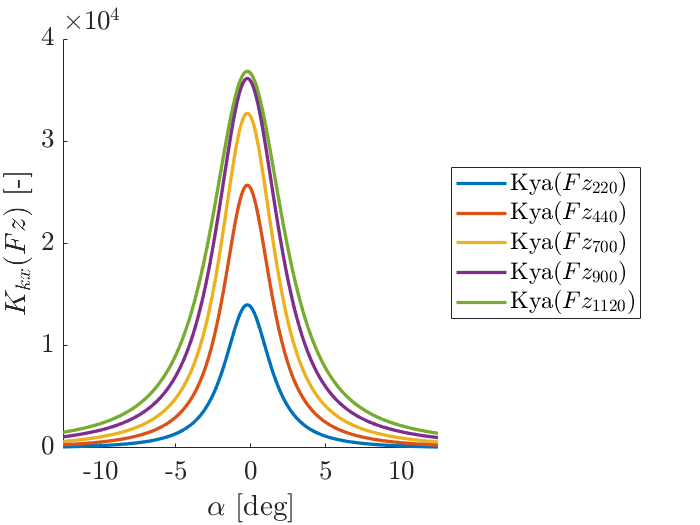


figure('Name','Kya(alpha): cornering stiffness as function of alpha','NumberTitle', 11 + last_fig_FX0)
hold on
plot(SA_vec*to_deg,Calfa_vec1_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec2_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec3_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec4_y,'-','LineWidth',2)
plot(SA_vec*to_deg,Calfa_vec5_y,'-','LineWidth',2)
hold off
legend({'Kya($Fz_{220}$)','Kya($Fz_{440}$)','Kya($Fz_{700}$)','Kya($Fz_{900}$)','Kya($Fz_{1120}$)'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$K_{kx}(Fz)$ [-]')

## ---FY0(gamma): fitting with variable camber(gamma)

extract data with the same vertical load (Fz = 220N) 

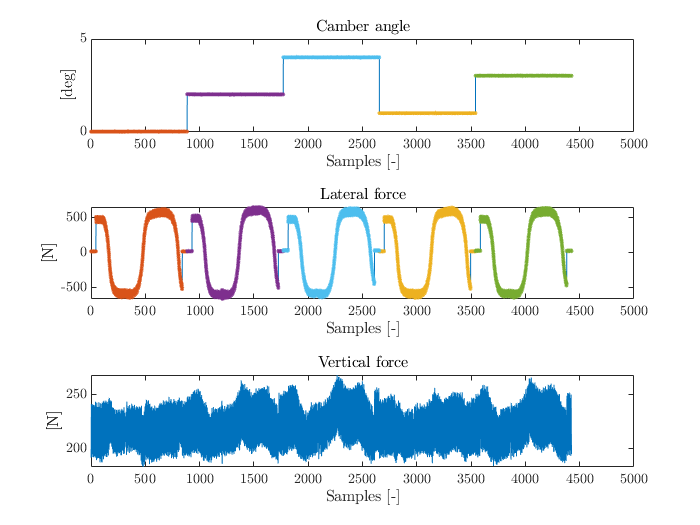

TDataGamma_pl = FZ_220_pl;

smpl_range_pl_dgamma = size(TDataGamma_pl);
vec_samples_pl_dgamma = 1:1:smpl_range_pl_dgamma;

% Extract points at constant camber
GAMMA_tol_pl_dgamma = 0.05*to_rad;
idx_pl_dgamma.GAMMA_0 = 0.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 0.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_1 = 1.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 1.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_2 = 2.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 2.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_3 = 3.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 3.0*to_rad+GAMMA_tol_pl_dgamma;
idx_pl_dgamma.GAMMA_4 = 4.0*to_rad-GAMMA_tol_pl_dgamma < TDataGamma_pl.IA & TDataGamma_pl.IA < 4.0*to_rad+GAMMA_tol_pl_dgamma;

GAMMA_0_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_0, : );
GAMMA_1_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_1, : );
GAMMA_2_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_2, : );
GAMMA_3_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_3, : );
GAMMA_4_dgamma  = TDataGamma_pl( idx_pl_dgamma.GAMMA_4, : );

% Plot
figure('Name','FY0(gamma): considered dataset', 'NumberTitle', 12 + last_fig_FX0)
tiledlayout(3,1)
ax_list_4(1) = nexttile;
plot(TDataGamma_pl.IA*to_deg)
hold on
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_0),GAMMA_0_dgamma.IA*to_deg,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_1),GAMMA_1_dgamma.IA*to_deg,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_2),GAMMA_2_dgamma.IA*to_deg,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_3),GAMMA_3_dgamma.IA*to_deg,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_4),GAMMA_4_dgamma.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')
hold off

ax_list_4(2) = nexttile;
plot(TDataGamma_pl.FY)
hold on
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_0),GAMMA_0_dgamma.FY,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_1),GAMMA_1_dgamma.FY,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_2),GAMMA_2_dgamma.FY,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_3),GAMMA_3_dgamma.FY,'.');
plot(vec_samples_pl_dgamma(idx_pl_dgamma.GAMMA_4),GAMMA_4_dgamma.FY,'.');
title('Lateral force')
xlabel('Samples [-]')
ylabel('[N]')
hold off

ax_list_4(3) = nexttile;
plot(TDataGamma_pl.FZ)
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')
linkaxes(ax_list_4,'x')

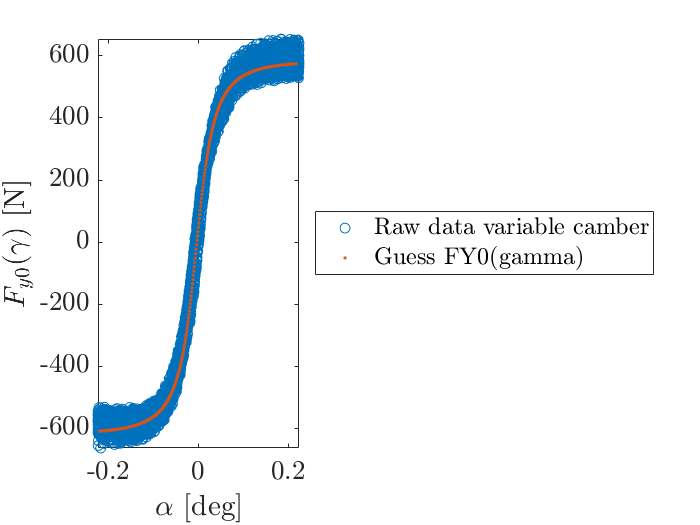


% Fit the coeffs {pDy3, pEy3, pEy4, pHy3, pKy3, pVy3, pVy4}

% Guess values for parameters to be optimised
%   [pDy3, pEy3, pEy4, pHy3, pKy3, pVy3, pVy4]
P0_FY0_dgamma = [ -2,  0 , -2 , 0 , 0 , 0.15 , 0 ];


% Limits for parameters to be optimised
%   [pDy3, pEy3, pEy4, pHy3, pKy3, pVy3, pVy4]
lb_FY0_dgamma = [-100, -100, -3, -100, -100, -100, -100 ];
ub_FY0_dgamma = [ 100, 100, 100, 100, 100, 100, 100];

zeros_vec_dgamma = zeros(size(TDataGamma_pl.IA));
ones_vec_dgamma  = ones(size(TDataGamma_pl.IA));

ALPHA_vec_dgamma = TDataGamma_pl.SA; 
GAMMA_vec_dgamma = TDataGamma_pl.IA; 
FY_vec_dgamma    = TDataGamma_pl.FY;
FZ_vec_dgamma    = TDataGamma_pl.FZ;

[FY0_varGamma_vec,~] = MF96_FY0_vec(zeros(size(SA_vec)), SA_vec , GAMMA_vec_dgamma, tyre_coeffs_pl.FZ0*ones(size(SA_vec)),tyre_coeffs_pl);

figure('Name','FY0(gamma): guess', 'NumberTitle', 13 + last_fig_FX0)
plot(ALPHA_vec_dgamma,TDataGamma_pl.FY,'o')
hold on
plot(SA_vec,FY0_varGamma_vec,'.','MarkerSize',5)
legend({'Raw data variable camber','Guess FY0(gamma)'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}(\gamma)$ [N]')


% Residual minimization
[P__FY0_dgamma,fval_FY0_dgamma,exitflag_FY0_dgamma] = fmincon(@(P)resid_pure_Fy_varGamma(P,FY_vec_dgamma, ALPHA_vec_dgamma,GAMMA_vec_dgamma,tyre_coeffs_pl.FZ0, tyre_coeffs_pl),...
                               P0_FY0_dgamma,[],[],[],[],lb_FY0_dgamma,ub_FY0_dgamma);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


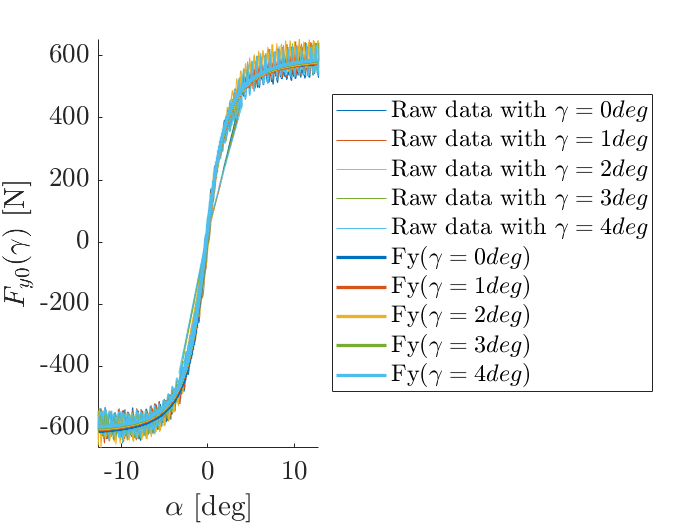


% Change tyre data with new optimal values                             
tyre_coeffs_pl.pDy3 = P__FY0_dgamma(1);  
tyre_coeffs_pl.pEy3 = P__FY0_dgamma(2); 
tyre_coeffs_pl.pEy4 = P__FY0_dgamma(3); 
tyre_coeffs_pl.pHy3 = P__FY0_dgamma(4); 
tyre_coeffs_pl.pKy3 = P__FY0_dgamma(5); 
tyre_coeffs_pl.pVy3 = P__FY0_dgamma(6); 
tyre_coeffs_pl.pVy4 = P__FY0_dgamma(7); 

tmp_zeros_dgamma = zeros(size(SA_vec));
tmp_ones_dgamma = ones(size(SA_vec));

[FY0_gamma_var_vec1,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_0_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
[FY0_gamma_var_vec2,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_1_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
[FY0_gamma_var_vec3,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_2_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
[FY0_gamma_var_vec4,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_3_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);
[FY0_gamma_var_vec5,~] = MF96_FY0_vec(tmp_zeros_dgamma, SA_vec ,mean(GAMMA_4_dgamma.IA)*tmp_ones_dgamma, mean(TDataGamma_pl.FZ)*tmp_ones_dgamma,tyre_coeffs_pl);


figure('Name','FY0(gamma): fitted with variable camber','NumberTitle', 14 + last_fig_FX0)
hold on
plot(GAMMA_0_dgamma.SA*to_deg,GAMMA_0_dgamma.FY,'-','MarkerSize',5, 'Color', '#0072BD') %'MarkerEdgeColor','y',
plot(GAMMA_1_dgamma.SA*to_deg,GAMMA_1_dgamma.FY,'-','MarkerSize',5, 'Color', '#D95319') %'MarkerEdgeColor','c',
plot(GAMMA_2_dgamma.SA*to_deg,GAMMA_2_dgamma.FY,'-','MarkerSize',5, 'Color', '#EDB120') %'MarkerEdgeColor','m',
plot(GAMMA_3_dgamma.SA*to_deg,GAMMA_3_dgamma.FY,'-','MarkerSize',5, 'Color', '#77AC30') %'MarkerEdgeColor','b',
plot(GAMMA_4_dgamma.SA*to_deg,GAMMA_4_dgamma.FY,'-','MarkerSize',5, 'Color', '#4DBEEE') %'MarkerEdgeColor','r',
plot(SA_vec*to_deg,FY0_gamma_var_vec1,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#0072BD')
plot(SA_vec*to_deg,FY0_gamma_var_vec2,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#D95319')
plot(SA_vec*to_deg,FY0_gamma_var_vec3,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#EDB120')
plot(SA_vec*to_deg,FY0_gamma_var_vec4,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#77AC30')
plot(SA_vec*to_deg,FY0_gamma_var_vec5,'-s','LineWidth',2,'MarkerSize',1, 'Color', '#4DBEEE')
legend({'Raw data with $\gamma = 0 deg $','Raw data with $\gamma = 1 deg $','Raw data with $\gamma = 2 deg $','Raw data with $\gamma = 3 deg $','Raw data with $\gamma = 4 deg $', 'Fy($\gamma = 0 deg$)','Fy($\gamma = 1 deg$)','Fy($\gamma = 2 deg$)','Fy($\gamma = 3 deg$)','Fy($\gamma = 4 deg$)'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$F_{y0}(\gamma)$ [N]')


% Calculate the residuals with the optimal solution found above
res_Fy0_dgamma  = resid_pure_Fy_varGamma(P__FY0_dgamma,FY_vec_dgamma, ALPHA_vec_dgamma,GAMMA_vec_dgamma,tyre_coeffs_pl.FZ0, tyre_coeffs_pl);

% Coefficients (used to check)
coeffs_FY0 = zeros(9,1);

[alpha__y, By, Cy, Dy, Ey, SVy, Kya, SHy, mu__y] = MF96_FY0_coeffs(0, 0, 2*to_rad, 1120, tyre_coeffs_pl);

coeffs_FY0(1) = alpha__y;
coeffs_FY0(2) = By;
coeffs_FY0(3) = Cy;
coeffs_FY0(4) = Dy;
coeffs_FY0(5) = Ey;
coeffs_FY0(6) = SVy;
coeffs_FY0(7) = Kya;
coeffs_FY0(8) = SHy;
coeffs_FY0(9) = mu__y;

% % R-squared is 
% % 1-SSE/SST
% % SSE/SST = res_Fx0_nom
% 
% % SSE is the sum of squared error,  SST is the sum of squared total
% fprintf('R-squared = %6.3f\n',1-res_Fx0_varGamma);

## ---------------last figure FY0---------------

last_fig_FY0 = 13 + last_fig_FX0;

## --Pure self aligning moment MZO: same dataset (lateral)

cut_start_mz = 27760;
cut_end_mz = 54500;

% select dataset portion
smpl_range_mz = cut_start_mz:cut_end_mz;

## ---------------last figure MZ0---------------

last_fig_MZ0 = 10 + last_fig_FY0;

## --Combined longitudinal force FX: dataset import

% Change dataset: load and select the region analysis
data_set = 'Hoosier_B1464run30'; % combined behaviour

fprintf('Loading dataset: ')

Loading dataset: 


switch data_set
  case 'Hoosier_B1464run30'
      fprintf('for combined behaviour analysis.')
      load ([data_set_path, data_set]);

  otherwise 
  error('Not found dataset: `%s`\n', data_set) ;
  
end

for combined behaviour analysis.


% select dataset portion (at the higher pressure)
cut_start_comb = 19030;
cut_end_comb   = 38170;


smpl_range_comb = cut_start_comb:cut_end_comb;

fprintf('\ncompleted!')


completed!

## ---Dataset for combined behaviour: plot

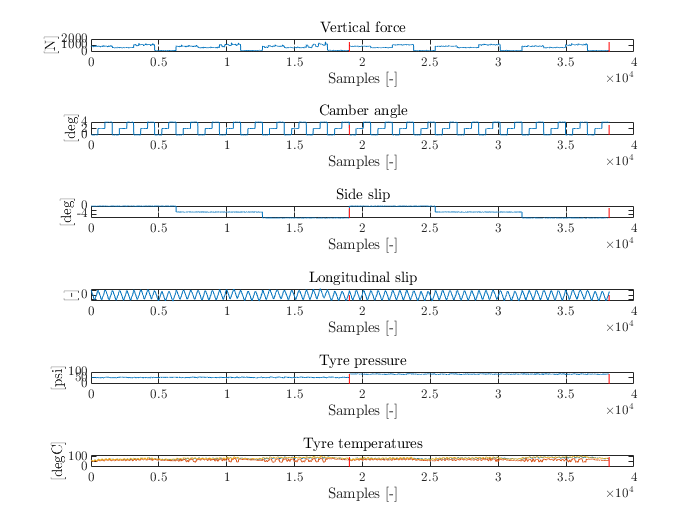

figure ('Name','CombFXFY: entire raw dataset', 'NumberTitle',1+ last_fig_MZ0)
tiledlayout(6,1)

ax_list_5(1) = nexttile; y_range = [min(min(-FZ),0) round(max(-FZ)*1.1)];
plot(-FZ)
hold on
plot([cut_start_comb cut_start_comb],y_range,'--r')
plot([cut_end_comb cut_end_comb],y_range,'--r')
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list_5(2) = nexttile; y_range = [min(min(IA),0) round(max(IA)*1.1)];
plot(IA)
hold on
plot([cut_start_comb cut_start_comb],y_range,'--r')
plot([cut_end_comb cut_end_comb],y_range,'--r')
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_5(3) = nexttile; y_range = [min(min(SA),0) round(max(SA)*1.1)];
plot(SA)
hold on
plot([cut_start_comb cut_start_comb],y_range,'--r')
plot([cut_end_comb cut_end_comb],y_range,'--r')
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_5(4) = nexttile; y_range = [min(min(SL),0) round(max(SL)*1.1)];
plot(SL)
hold on
plot([cut_start_comb cut_start_comb],y_range,'--r')
plot([cut_end_comb cut_end_comb],y_range,'--r')
title('Longitudinal slip')
xlabel('Samples [-]')
ylabel('[-]')

ax_list_5(5) = nexttile; y_range = [min(min(P),0) round(max(P)*1.1)];
plot(P)
hold on
plot([cut_start_comb cut_start_comb],y_range,'--r')
plot([cut_end_comb cut_end_comb],y_range,'--r')
title('Tyre pressure')
xlabel('Samples [-]')
ylabel('[psi]')

ax_list_5(6) = nexttile;  y_range = [min(min(TSTC),0) round(max(TSTC)*1.1)];
plot(TSTC,'DisplayName','Center')
hold on
plot(TSTI,'DisplayName','Internal')
plot(TSTO,'DisplayName','Outboard')
hold on
plot([cut_start_comb cut_start_comb],y_range,'--r')
plot([cut_end_comb cut_end_comb],y_range,'--r')
title('Tyre temperatures')
xlabel('Samples [-]')
ylabel('[degC]')

linkaxes(ax_list_5,'x')

## ---Higher pressure dataset for combined behaviour: table selection and plot

for different camber angle, vertical load and side slip angle

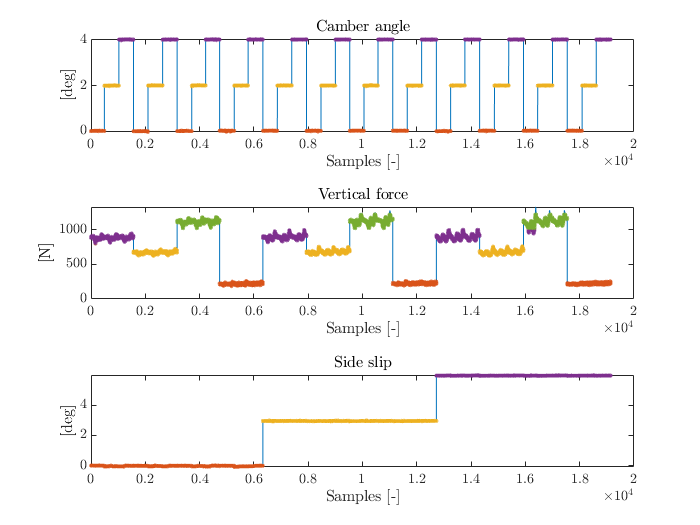

vec_samples_comb = 1:1:length(smpl_range_comb);

tyre_data_comb = table(); % create empty table
% store raw data in table
tyre_data_comb.SL =  SL(smpl_range_comb);
tyre_data_comb.SA = -SA(smpl_range_comb)*to_rad;    % SAE -> Adapted SAE
tyre_data_comb.FZ = -FZ(smpl_range_comb);           % SAE -> Adapted SAE
tyre_data_comb.FX =  FX(smpl_range_comb);
tyre_data_comb.FY =  FY(smpl_range_comb);   
tyre_data_comb.MZ =  MZ(smpl_range_comb);
tyre_data_comb.IA =  IA(smpl_range_comb)*to_rad;

% Extract points at constant camber angle
GAMMA_tol_comb = 0.05*to_rad;
idx_comb.GAMMA_0 = 0.0*to_rad-GAMMA_tol_comb < tyre_data_comb.IA & tyre_data_comb.IA < 0.0*to_rad+GAMMA_tol_comb;
idx_comb.GAMMA_1 = 1.0*to_rad-GAMMA_tol_comb < tyre_data_comb.IA & tyre_data_comb.IA < 1.0*to_rad+GAMMA_tol_comb;
idx_comb.GAMMA_2 = 2.0*to_rad-GAMMA_tol_comb < tyre_data_comb.IA & tyre_data_comb.IA < 2.0*to_rad+GAMMA_tol_comb;
idx_comb.GAMMA_3 = 3.0*to_rad-GAMMA_tol_comb < tyre_data_comb.IA & tyre_data_comb.IA < 3.0*to_rad+GAMMA_tol_comb;
idx_comb.GAMMA_4 = 4.0*to_rad-GAMMA_tol_comb < tyre_data_comb.IA & tyre_data_comb.IA < 4.0*to_rad+GAMMA_tol_comb;

GAMMA_0_comb  = tyre_data_comb( idx_comb.GAMMA_0, : );
GAMMA_1_comb  = tyre_data_comb( idx_comb.GAMMA_1, : );
GAMMA_2_comb  = tyre_data_comb( idx_comb.GAMMA_2, : );
GAMMA_3_comb  = tyre_data_comb( idx_comb.GAMMA_3, : );
GAMMA_4_comb  = tyre_data_comb( idx_comb.GAMMA_4, : );

% Extract points at constant vertical load
% Test data done at: 
%  - 50lbf  ( 50*0.453592*9.81 =  223N )
%  - 150lbf (150*0.453592*9.81 =  667N )
%  - 200lbf (200*0.453592*9.81 =  890N )
%  - 250lbf (250*0.453592*9.81 = 1120N )

FZ_tol_comb = 100;
idx_comb.FZ_220  = 220-FZ_tol_comb < tyre_data_comb.FZ & tyre_data_comb.FZ < 220+FZ_tol_comb;
idx_comb.FZ_700  = 700-FZ_tol_comb < tyre_data_comb.FZ & tyre_data_comb.FZ < 700+FZ_tol_comb;
idx_comb.FZ_900  = 900-FZ_tol_comb < tyre_data_comb.FZ & tyre_data_comb.FZ < 900+FZ_tol_comb;
idx_comb.FZ_1120 = 1120-FZ_tol_comb < tyre_data_comb.FZ & tyre_data_comb.FZ < 1120+FZ_tol_comb;
FZ_220_comb  = tyre_data_comb( idx_comb.FZ_220, : );
FZ_700_comb  = tyre_data_comb( idx_comb.FZ_700, : );
FZ_900_comb  = tyre_data_comb( idx_comb.FZ_900, : );
FZ_1120_comb = tyre_data_comb( idx_comb.FZ_1120, : );

% Extract the points at constant side slip angle
% 0° , 3° , 6 °
SA_tol_comb = 0.5*to_rad;
idx_comb.SA_0    =  0-SA_tol_comb      < tyre_data_comb.SA & tyre_data_comb.SA < 0+SA_tol_comb;
idx_comb.SA_3 = (3*to_rad-SA_tol_comb) < tyre_data_comb.SA & tyre_data_comb.SA < 3*to_rad+SA_tol_comb;
idx_comb.SA_6 = (6*to_rad-SA_tol_comb) < tyre_data_comb.SA & tyre_data_comb.SA < 6*to_rad+SA_tol_comb;
SA_0_comb     = tyre_data_comb( idx_comb.SA_0, : );
SA_3_comb     = tyre_data_comb( idx_comb.SA_3, : );
SA_6_comb     = tyre_data_comb( idx_comb.SA_6, : );

% Plot
figure('Name','CombFXFY: higher pressure dataset with regions', 'NumberTitle', 2 + last_fig_MZ0)
tiledlayout(3,1)

ax_list_6(1) = nexttile;
plot(tyre_data_comb.IA*to_deg)
hold on
plot(vec_samples_comb(idx_comb.GAMMA_0),GAMMA_0_comb.IA*to_deg,'.');
plot(vec_samples_comb(idx_comb.GAMMA_1),GAMMA_1_comb.IA*to_deg,'.');
plot(vec_samples_comb(idx_comb.GAMMA_2),GAMMA_2_comb.IA*to_deg,'.');
plot(vec_samples_comb(idx_comb.GAMMA_3),GAMMA_3_comb.IA*to_deg,'.');
plot(vec_samples_comb(idx_comb.GAMMA_4),GAMMA_4_comb.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')

ax_list_6(2) = nexttile;
plot(tyre_data_comb.FZ)
hold on
plot(vec_samples_comb(idx_comb.FZ_220),FZ_220_comb.FZ,'.');
%plot(vec_samples_comb(idx_comb.FZ_440),FZ_440_comb.FZ,'.');
plot(vec_samples_comb(idx_comb.FZ_700),FZ_700_comb.FZ,'.');
plot(vec_samples_comb(idx_comb.FZ_900),FZ_900_comb.FZ,'.');
plot(vec_samples_comb(idx_comb.FZ_1120),FZ_1120_comb.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')

ax_list_6(3) = nexttile;
plot(tyre_data_comb.SA*to_deg)
hold on
plot(vec_samples_comb(idx_comb.SA_0),SA_0_comb.SA*to_deg,'.');
plot(vec_samples_comb(idx_comb.SA_3),SA_3_comb.SA*to_deg,'.');
plot(vec_samples_comb(idx_comb.SA_6),SA_6_comb.SA*to_deg,'.');
title('Side slip')
xlabel('Samples [-]')
ylabel('[deg]')

hold off
linkaxes(ax_list_6,'x')

## ---FX: fitting in pure conditions (variable alpha, gamma = 0, Fz = 220N)

choose the range with: variable side slip angle, camber angle = 0, vertical load = 220N (obv within the higher pressure dataset)

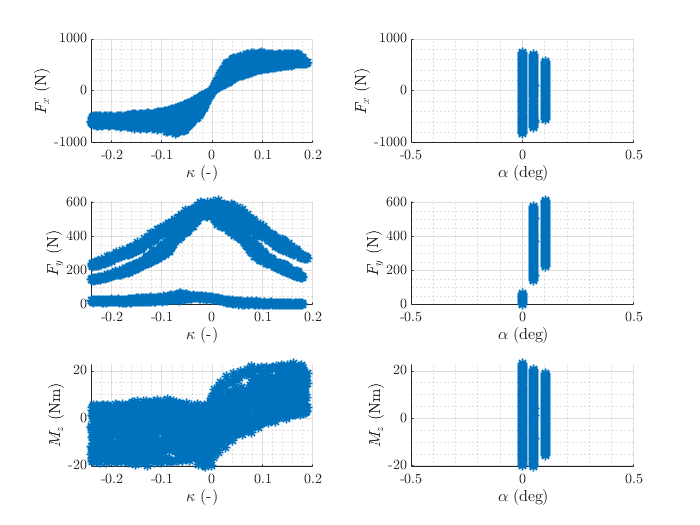

[TData_x_dalpha, ~] = intersect_table_data( GAMMA_0_comb, FZ_220_comb );

figure('Name','FX: dataset in pure conditions range', 'NumberTitle', 3 + last_fig_MZ0)
plot_selected_data(TData_x_dalpha);

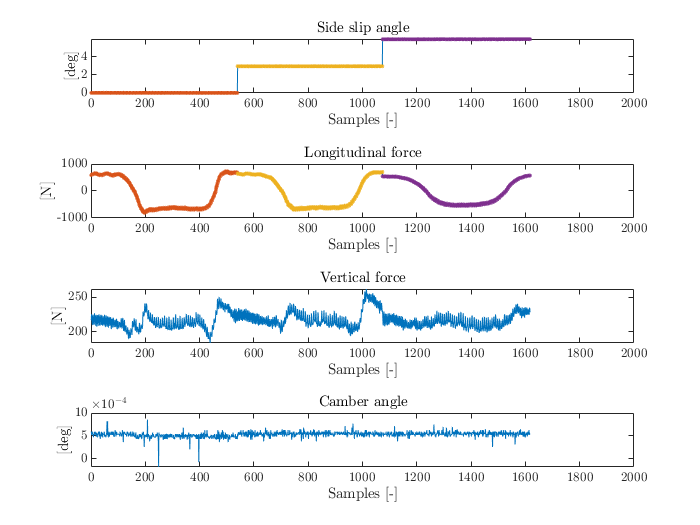


% extract data with variable side slip

smpl_range_x_dalpha = size(TData_x_dalpha);
vec_samples_x_dalpha = 1:1:smpl_range_x_dalpha;

% Extract points at constant side slip and plot
ALPHA_tol_x_dalpha = 0.5*to_rad;
idx_x_dalpha.ALPHA_0 = 0.0*to_rad-ALPHA_tol_x_dalpha < TData_x_dalpha.SA & TData_x_dalpha.SA < 0.0*to_rad+ALPHA_tol_x_dalpha;
idx_x_dalpha.ALPHA_3 = 3.0*to_rad-ALPHA_tol_x_dalpha < TData_x_dalpha.SA & TData_x_dalpha.SA < 3.0*to_rad+ALPHA_tol_x_dalpha;
idx_x_dalpha.ALPHA_6 = 6.0*to_rad-ALPHA_tol_x_dalpha < TData_x_dalpha.SA & TData_x_dalpha.SA < 6.0*to_rad+ALPHA_tol_x_dalpha;

ALPHA_0_dalpha  = TData_x_dalpha( idx_x_dalpha.ALPHA_0, : );
ALPHA_3_dalpha  = TData_x_dalpha( idx_x_dalpha.ALPHA_3, : );
ALPHA_6_dalpha  = TData_x_dalpha( idx_x_dalpha.ALPHA_6, : );

% Plot
figure('Name','FX: Considered ranges for pure conditions', 'NumberTitle', 4 + last_fig_MZ0)
tiledlayout(4,1)
ax_list_7(1) = nexttile;
plot(TData_x_dalpha.SA*to_deg)
hold on
plot(vec_samples_x_dalpha(idx_x_dalpha.ALPHA_0),ALPHA_0_dalpha.SA*to_deg,'.');
plot(vec_samples_x_dalpha(idx_x_dalpha.ALPHA_3),ALPHA_3_dalpha.SA*to_deg,'.');
plot(vec_samples_x_dalpha(idx_x_dalpha.ALPHA_6),ALPHA_6_dalpha.SA*to_deg,'.');
title('Side slip angle')
xlabel('Samples [-]')
ylabel('[deg]')
hold off

ax_list_7(2) = nexttile;
plot(TData_x_dalpha.FX)
hold on
plot(vec_samples_x_dalpha(idx_x_dalpha.ALPHA_0),ALPHA_0_dalpha.FX,'.');
plot(vec_samples_x_dalpha(idx_x_dalpha.ALPHA_3),ALPHA_3_dalpha.FX,'.');
plot(vec_samples_x_dalpha(idx_x_dalpha.ALPHA_6),ALPHA_6_dalpha.FX,'.');
title('Longitudinal force')
xlabel('Samples [-]')
ylabel('[N]')
hold off

ax_list_7(3) = nexttile;
plot(TData_x_dalpha.FZ)
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')
linkaxes(ax_list_7,'x')

ax_list_7(4) = nexttile;
plot(TData_x_dalpha.IA)
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')
linkaxes(ax_list_7,'x')



% Fit the coeffs {rBx1, rBx2, rCx1, rHx1}

% Guess values for parameters to be optimised
%   [rBx1, rBx2, rCx1, rHx1]
P0_FX_pure = [ 17 , -11 , 1 , 0 ];

% Limits for parameters to be optimised
lb_FX_pure = [ 0, -16.5, -0.5, -0.015 ];
ub_FX_pure = [ 20, 20, 10, 0.015];

zeros_vec_x_dalpha = zeros(size(TData_x_dalpha.IA));
ones_vec_x_dalpha  = ones(size(TData_x_dalpha.IA));

KAPPA_vec_x_dalpha = TData_x_dalpha.SL;
ALPHA_vec_x_dalpha = TData_x_dalpha.SA;
FX_vec_dalpha    = TData_x_dalpha.FX;
FZ_vec_dalpha    = TData_x_dalpha.FZ;


% Minimize the residual:
[P_opt_FX_pure,fval_FX_pure,exitflag_FX_pure] = fmincon(@(P)resid_Fx_varAlpha(P,FX_vec_dalpha, KAPPA_vec_x_dalpha, ALPHA_vec_x_dalpha, zeros_vec_x_dalpha,tyre_coeffs_pl.FZ0*ones_vec_x_dalpha, tyre_coeffs_pl),...
                               P0_FX_pure,[],[],[],[],lb_FX_pure,ub_FX_pure);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


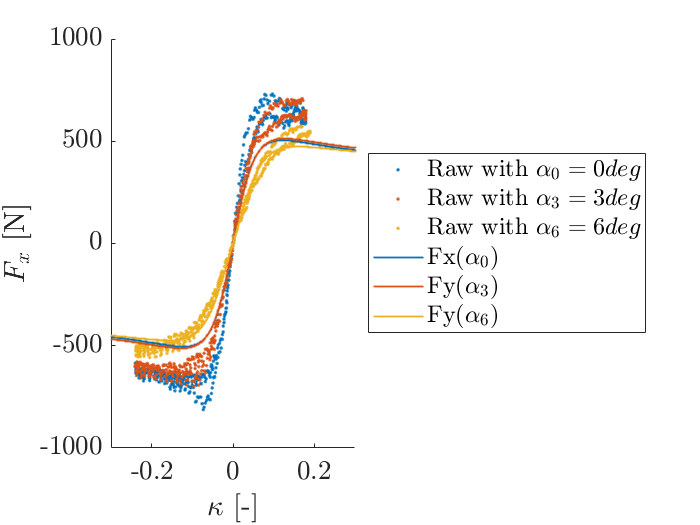


% Change tyre data with new optimal values                             
    tyre_coeffs_pl.rBx1 = P_opt_FX_pure(1);  
    tyre_coeffs_pl.rBx2 = P_opt_FX_pure(2); 
    tyre_coeffs_pl.rCx1 = P_opt_FX_pure(3); 
    tyre_coeffs_pl.rHx1 = P_opt_FX_pure(4); 

% Check residuals!

tmp_zeros_dalpha = zeros(size(SL_vec));
tmp_ones_dalpha = ones(size(SL_vec));

[FX_alpha_var_vec1, Gxa_alpha_var_vec1] = MF96_FX_vec(SL_vec, mean(ALPHA_0_dalpha.SA)*tmp_ones_dalpha , tmp_zeros_dalpha, mean(ALPHA_0_dalpha.FZ)*tmp_ones_dalpha, tyre_coeffs_pl);
[FX_alpha_var_vec2, Gxa_alpha_var_vec2] = MF96_FX_vec(SL_vec, mean(ALPHA_3_dalpha.SA)*tmp_ones_dalpha , tmp_zeros_dalpha, mean(ALPHA_3_dalpha.FZ)*tmp_ones_dalpha,tyre_coeffs_pl);
[FX_alpha_var_vec3, Gxa_alpha_var_vec3] = MF96_FX_vec(SL_vec, mean(ALPHA_6_dalpha.SA)*tmp_ones_dalpha , tmp_zeros_dalpha, mean(ALPHA_6_dalpha.FZ)*tmp_ones_dalpha,tyre_coeffs_pl);

[~, Gxa_gamma_var_vec1] = MF96_FX_vec(0*ones(size(SA_vec)) , SA_vec , zeros(size(SA_vec)), mean(ALPHA_0_dalpha.FZ)*ones(size(SA_vec)), tyre_coeffs_pl);
[~, Gxa_gamma_var_vec2] = MF96_FX_vec(0.1*ones(size(SA_vec)) , SA_vec , zeros(size(SA_vec)), mean(ALPHA_3_dalpha.FZ)*ones(size(SA_vec)),tyre_coeffs_pl);
[~, Gxa_gamma_var_vec3] = MF96_FX_vec(0.3*ones(size(SA_vec)) , SA_vec , zeros(size(SA_vec)), mean(ALPHA_6_dalpha.FZ)*ones(size(SA_vec)),tyre_coeffs_pl);


figure('Name','FX(kappa): fitted in pure conditions','NumberTitle', 5 + last_fig_MZ0)
hold on
plot(ALPHA_0_dalpha.SL,ALPHA_0_dalpha.FX,'.','MarkerSize',5, 'Color', '#0072BD') %'MarkerEdgeColor','y',
plot(ALPHA_3_dalpha.SL,ALPHA_3_dalpha.FX,'.','MarkerSize',5, 'Color', '#D95319') %'MarkerEdgeColor','c',
plot(ALPHA_6_dalpha.SL,ALPHA_6_dalpha.FX,'.','MarkerSize',5, 'Color', '#EDB120') %'MarkerEdgeColor','m',

plot(SL_vec,FX_alpha_var_vec1,'-s','LineWidth',1,'MarkerSize',1, 'Color', '#0072BD')
plot(SL_vec,FX_alpha_var_vec2,'-s','LineWidth',1,'MarkerSize',1, 'Color', '#D95319')
plot(SL_vec,FX_alpha_var_vec3,'-s','LineWidth',1,'MarkerSize',1, 'Color', '#EDB120')
legend({'Raw with $\alpha_0 = 0 deg $','Raw with $\alpha_3 = 3 deg $','Raw with $ \alpha_6 = 6 deg $', 'Fx($\alpha_0$)','Fy($\alpha_3$)','Fy($\alpha_6$)'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{x}$ [N]')

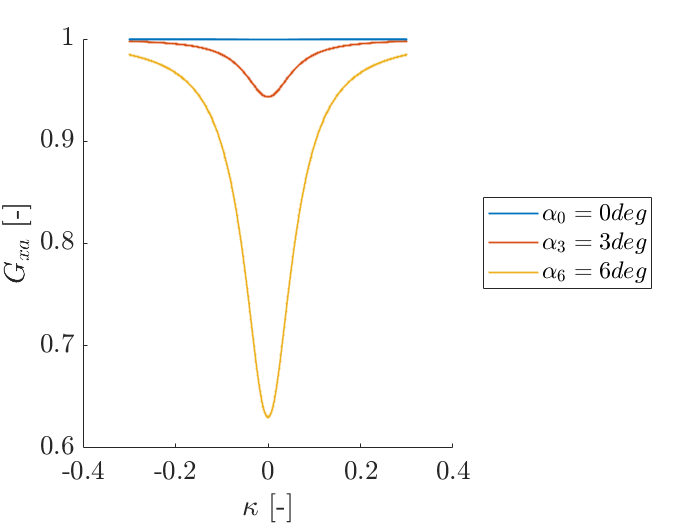


figure('Name','Gxa(kappa) as function of kappa','NumberTitle', 6 + last_fig_MZ0)
hold on
plot(SL_vec,Gxa_alpha_var_vec1,'-s','LineWidth',1,'MarkerSize',1)
plot(SL_vec,Gxa_alpha_var_vec2,'-s','LineWidth',1,'MarkerSize',1)
plot(SL_vec,Gxa_alpha_var_vec3,'-s','LineWidth',1,'MarkerSize',1)
legend({'$ \alpha_0 = 0 deg $','$ \alpha_3 = 3 deg $','$ \alpha_6 = 6 deg $'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$G_{xa}$ [-]')

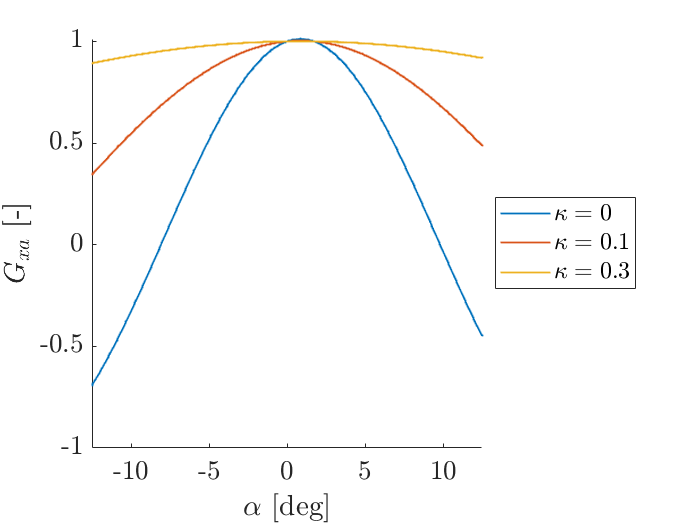


figure('Name','Gxa(alpha) as function of alpha','NumberTitle', 7 + last_fig_MZ0)
hold on
plot(SA_vec*to_deg,Gxa_gamma_var_vec1,'-s','LineWidth',1,'MarkerSize',1)
plot(SA_vec*to_deg,Gxa_gamma_var_vec2,'-s','LineWidth',1,'MarkerSize',1)
plot(SA_vec*to_deg,Gxa_gamma_var_vec3,'-s','LineWidth',1,'MarkerSize',1)
legend({'$ \kappa = 0 $','$ \kappa = 0.1 $','$ \kappa = 0.3 $'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$G_{xa}$ [-]')

## ---------------last figure FX---------------

For figure number:

last_fig_FX = 7 + last_fig_MZ0;

## --Combined longitudinal force FY: same dataset (combined)

## ---FY: fitting in pure conditions (variable alpha, gamma = 0, Fz = 220N)

choose the range with: variable side slip angle, camber angle = 0, vertical load = 220N (obv within the higher pressure dataset)

% Fit the coeffs {rBy1, rBy2, rBy3, rCy1, rHy1, rVy1, rVy4, rVy5, rVy6}

% Guess values for parameters to be optimised
%            [ rBy1, rBy2, rBy3, rCy1, rHy1, rVy1, rVy4, rVy5, rVy6 ]
%P0_FY_pure = [ 10 , 7.5, 1.05 , 0.01 , 0.01 , 0.05 , 95 , 2 ,24  ];
P0_FY_pure = [ 14 , 13, -0.5 , 0.98 , 0.03 , -0.23 , 3.8 , -0.1 , 28.4  ];

% Limits for parameters to be optimised
lb_FY_pure = [ ];
ub_FY_pure = [ ];

zeros_vec_y_dalpha = zeros(size(TData_x_dalpha.IA));
ones_vec_y_dalpha  = ones(size(TData_x_dalpha.IA));

KAPPA_vec_y_dalpha = TData_x_dalpha.SL;
ALPHA_vec_y_dalpha = TData_x_dalpha.SA;
FY_vec_dalpha    = TData_x_dalpha.FY;


% % Minimize the residual:
[P_opt_FY_pure,fval_FY_pure,exitflag_FY_pure] = fmincon(@(P)resid_Fy_varAlpha(P,FY_vec_dalpha, KAPPA_vec_y_dalpha, ALPHA_vec_y_dalpha, zeros_vec_y_dalpha,tyre_coeffs_pl.FZ0*ones_vec_y_dalpha, tyre_coeffs_pl),...
                               P0_FY_pure,[],[],[],[],lb_FY_pure,ub_FY_pure);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


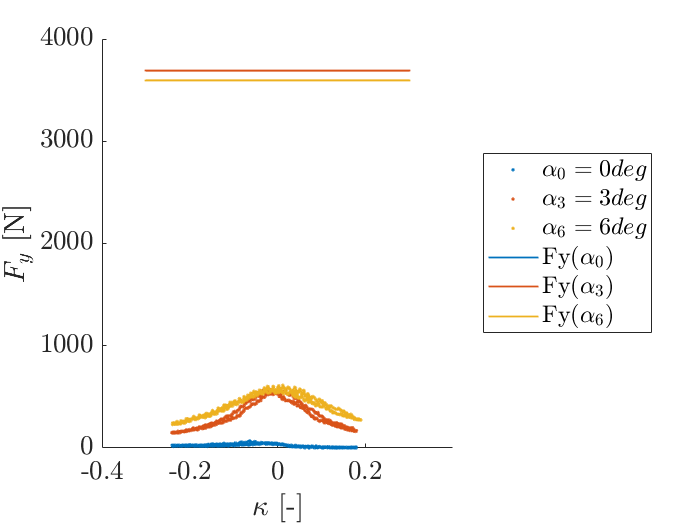


% Change tyre data with new optimal values                             
%     tyre_coeffs_pl.rBy1 = 10;
%     tyre_coeffs_pl.rBy2 = 10;
%     tyre_coeffs_pl.rBy3 = 0.0025;
%     tyre_coeffs_pl.rCy1 = 1.0587;
%     tyre_coeffs_pl.rHy1 =0.009472;
%     tyre_coeffs_pl.rVy1 = 0.05187;
%     tyre_coeffs_pl.rVy4 = 94.63;
%     tyre_coeffs_pl.rVy5 = 1.8914;
%     tyre_coeffs_pl.rVy6 = 23.8;
tyre_coeffs_pl.pCy1 = P_opt_FY_pure(1) ;
tyre_coeffs_pl.pDy1 = P_opt_FY_pure(2) ;  
tyre_coeffs_pl.pEy1 = P_opt_FY_pure(3) ;
tyre_coeffs_pl.pHy1 = P_opt_FY_pure(4) ;
tyre_coeffs_pl.pKy1 = P_opt_FY_pure(5) ; 
tyre_coeffs_pl.pKy2 = P_opt_FY_pure(6) ;
tyre_coeffs_pl.pVy1 = P_opt_FY_pure(7) ;

% Check residuals!


tmp_zeros_dalpha = zeros(size(SL_vec));
tmp_ones_dalpha = ones(size(SL_vec));

[FY_alpha_var_vec1, Gyk_alpha_var_vec1] = MF96_FY_vec(SL_vec, mean(ALPHA_0_dalpha.SA)*tmp_ones_dalpha , tmp_zeros_dalpha, mean(ALPHA_0_dalpha.FZ)*tmp_ones_dalpha, tyre_coeffs_pl);
[FY_alpha_var_vec2, Gyk_alpha_var_vec2] = MF96_FY_vec(SL_vec, mean(ALPHA_3_dalpha.SA)*tmp_ones_dalpha , tmp_zeros_dalpha, mean(ALPHA_3_dalpha.FZ)*tmp_ones_dalpha,tyre_coeffs_pl);
[FY_alpha_var_vec3, Gyk_alpha_var_vec3] = MF96_FY_vec(SL_vec, mean(ALPHA_6_dalpha.SA)*tmp_ones_dalpha , tmp_zeros_dalpha, mean(ALPHA_6_dalpha.FZ)*tmp_ones_dalpha,tyre_coeffs_pl);

[~, Gyk_gamma_var_vec1] = MF96_FY_vec(0*ones(size(SA_vec)) , SA_vec , zeros(size(SA_vec)), mean(ALPHA_0_dalpha.FZ)*ones(size(SA_vec)), tyre_coeffs_pl);
[~, Gyk_gamma_var_vec2] = MF96_FY_vec(0.1*ones(size(SA_vec)) , SA_vec , zeros(size(SA_vec)), mean(ALPHA_3_dalpha.FZ)*ones(size(SA_vec)),tyre_coeffs_pl);
[~, Gyk_gamma_var_vec3] = MF96_FY_vec(0.3*ones(size(SA_vec)) , SA_vec , zeros(size(SA_vec)), mean(ALPHA_6_dalpha.FZ)*ones(size(SA_vec)),tyre_coeffs_pl);

figure('Name','FY(kappa): fitted in pure conditions')
hold on
plot(ALPHA_0_dalpha.SL,ALPHA_0_dalpha.FY,'.','MarkerSize',5, 'Color', '#0072BD') %'MarkerEdgeColor','y',
plot(ALPHA_3_dalpha.SL,ALPHA_3_dalpha.FY,'.','MarkerSize',5, 'Color', '#D95319') %'MarkerEdgeColor','c',
plot(ALPHA_6_dalpha.SL,ALPHA_6_dalpha.FY,'.','MarkerSize',5, 'Color', '#EDB120') %'MarkerEdgeColor','m',

plot(SL_vec,FY_alpha_var_vec1,'-s','LineWidth',1,'MarkerSize',1, 'Color', '#0072BD')
plot(SL_vec,FY_alpha_var_vec2,'-s','LineWidth',1,'MarkerSize',1, 'Color', '#D95319')
plot(SL_vec,FY_alpha_var_vec3,'-s','LineWidth',1,'MarkerSize',1, 'Color', '#EDB120')
legend({'$ \alpha_0 = 0 deg $','$ \alpha_3 = 3 deg $','$ \alpha_6 = 6 deg $', 'Fy($\alpha_0$)','Fy($\alpha_3$)','Fy($\alpha_6$)'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{y}$ [N]')

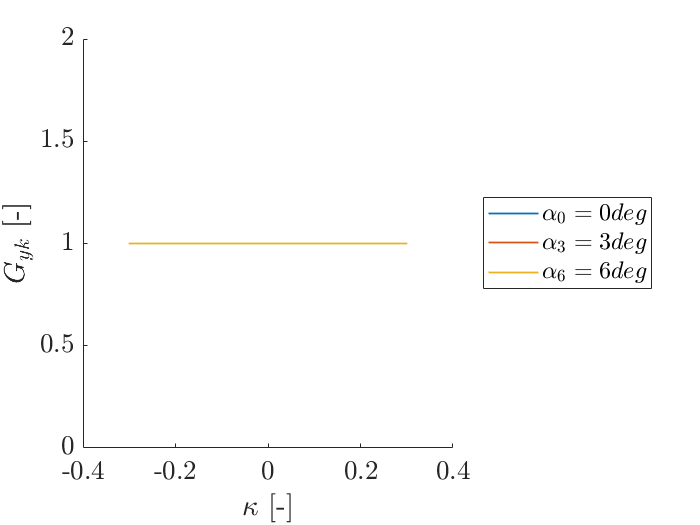


figure('Name','Gyk(kappa) as function of kappa','NumberTitle', 2 + last_fig_FX)
hold on
plot(SL_vec,Gyk_alpha_var_vec1,'-s','LineWidth',1,'MarkerSize',1)
plot(SL_vec,Gyk_alpha_var_vec2,'-s','LineWidth',1,'MarkerSize',1)
plot(SL_vec,Gyk_alpha_var_vec3,'-s','LineWidth',1,'MarkerSize',1)
legend({'$ \alpha_0 = 0 deg $','$ \alpha_3 = 3 deg $','$ \alpha_6 = 6 deg $'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$G_{yk}$ [-]')

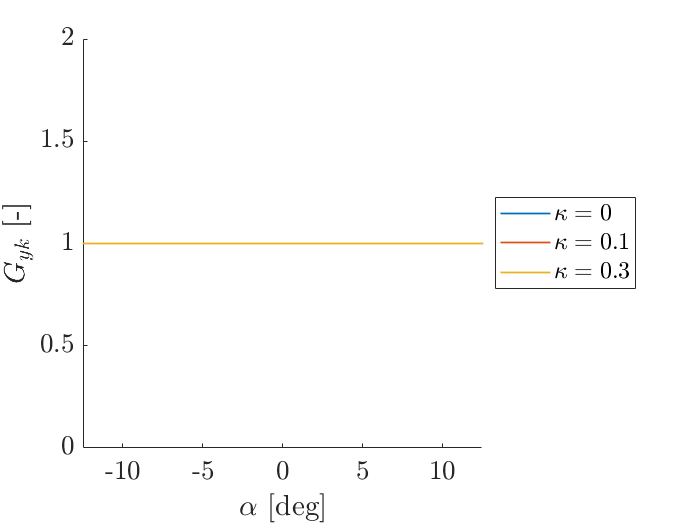


% To be done!
figure('Name','Gyk(alpha) as function of alpha','NumberTitle', 3 + last_fig_FX)
hold on
plot(SA_vec*to_deg,Gyk_gamma_var_vec1,'-s','LineWidth',1,'MarkerSize',1)
plot(SA_vec*to_deg,Gyk_gamma_var_vec2,'-s','LineWidth',1,'MarkerSize',1)
plot(SA_vec*to_deg,Gyk_gamma_var_vec3,'-s','LineWidth',1,'MarkerSize',1)
legend({'$ \kappa = 0 $','$ \kappa = 0.1 $','$ \kappa = 0.3 $'}, 'Location','eastoutside');
xlabel('$\alpha$ [deg]')
ylabel('$G_{yk}$ [-]')

## ---FY(Fz): fitting with variable Fz

Consider the 4 cases of different vertical load and camber angle = 0, obv variable alpha

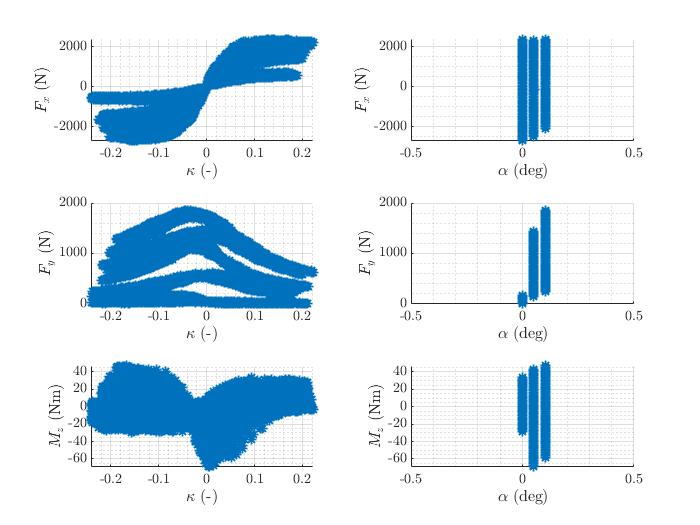

TData_y_comb_dFz = GAMMA_0_comb;

figure('Name','FY(Fz): considered dataset', 'NumberTitle', 4 + last_fig_FX)
plot_selected_data(TData_y_comb_dFz);

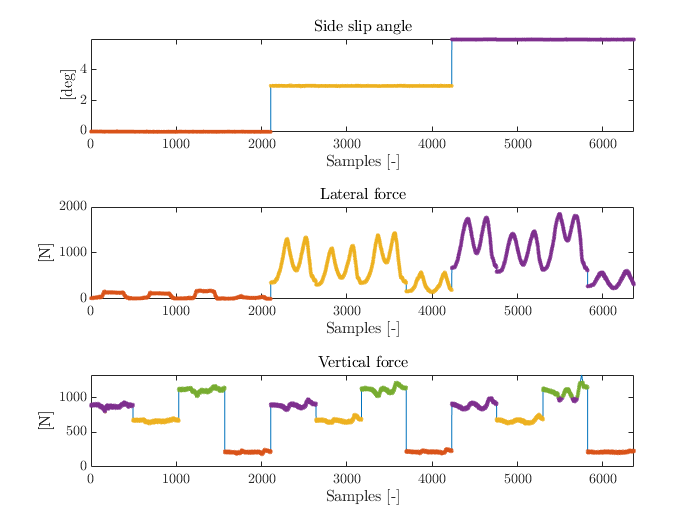


%Extract various load conditions
% =data with 0 camber and variable load

smpl_range_y_comb_dFz = size(TData_y_comb_dFz);
vec_samples_y_comb_dFz = 1:1:smpl_range_y_comb_dFz;

% Extract points at constant side slip and plot
ALPHA_tol_y_comb_dFz = 0.5*to_rad;
idx_y_comb_dFz.ALPHA_0 = 0.0*to_rad-ALPHA_tol_y_comb_dFz < TData_y_comb_dFz.SA & TData_y_comb_dFz.SA < 0.0*to_rad+ALPHA_tol_y_comb_dFz;
idx_y_comb_dFz.ALPHA_3 = 3.0*to_rad-ALPHA_tol_y_comb_dFz < TData_y_comb_dFz.SA & TData_y_comb_dFz.SA < 3.0*to_rad+ALPHA_tol_y_comb_dFz;
idx_y_comb_dFz.ALPHA_6 = 6.0*to_rad-ALPHA_tol_y_comb_dFz < TData_y_comb_dFz.SA & TData_y_comb_dFz.SA < 6.0*to_rad+ALPHA_tol_y_comb_dFz;

ALPHA_0_y_comb_dFz  = TData_y_comb_dFz( idx_y_comb_dFz.ALPHA_0, : );
ALPHA_3_y_comb_dFz  = TData_y_comb_dFz( idx_y_comb_dFz.ALPHA_3, : );
ALPHA_6_y_comb_dFz  = TData_y_comb_dFz( idx_y_comb_dFz.ALPHA_6, : );


FZ_tol_y_comb_dFz = 100;
idx_y_comb_dFz.FZ_220  = 220-FZ_tol_y_comb_dFz < TData_y_comb_dFz.FZ & TData_y_comb_dFz.FZ < 220+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.FZ_700  = 700-FZ_tol_y_comb_dFz < TData_y_comb_dFz.FZ & TData_y_comb_dFz.FZ < 700+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.FZ_900  = 900-FZ_tol_y_comb_dFz < TData_y_comb_dFz.FZ & TData_y_comb_dFz.FZ < 900+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.FZ_1120 = 1120-FZ_tol_y_comb_dFz < TData_y_comb_dFz.FZ & TData_y_comb_dFz.FZ < 1120+FZ_tol_y_comb_dFz;
FZ_220_y_comb_dFz  = TData_y_comb_dFz( idx_y_comb_dFz.FZ_220, : );
FZ_700_y_comb_dFz  = TData_y_comb_dFz( idx_y_comb_dFz.FZ_700, : );
FZ_900_y_comb_dFz  = TData_y_comb_dFz( idx_y_comb_dFz.FZ_900, : );
FZ_1120_y_comb_dFz = TData_y_comb_dFz( idx_y_comb_dFz.FZ_1120, : );

% Ranges for plot (Skip)
idx_y_comb_dFz.alpha0_FZ_220  = 220-FZ_tol_y_comb_dFz < ALPHA_0_y_comb_dFz.FZ & ALPHA_0_y_comb_dFz.FZ < 220+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha0_FZ_700  = 700-FZ_tol_y_comb_dFz < ALPHA_0_y_comb_dFz.FZ & ALPHA_0_y_comb_dFz.FZ < 700+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha0_FZ_900  = 900-FZ_tol_y_comb_dFz < ALPHA_0_y_comb_dFz.FZ & ALPHA_0_y_comb_dFz.FZ < 900+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha0_FZ_1120 = 1120-FZ_tol_y_comb_dFz < ALPHA_0_y_comb_dFz.FZ & ALPHA_0_y_comb_dFz.FZ < 1120+FZ_tol_y_comb_dFz;
alpha0_FZ_220_y_comb_dFz  = ALPHA_0_y_comb_dFz( idx_y_comb_dFz.alpha0_FZ_220, : );
alpha0_FZ_700_y_comb_dFz  = ALPHA_0_y_comb_dFz( idx_y_comb_dFz.alpha0_FZ_700, : );
alpha0_FZ_900_y_comb_dFz  = ALPHA_0_y_comb_dFz( idx_y_comb_dFz.alpha0_FZ_900, : );
alpha0_FZ_1120_y_comb_dFz = ALPHA_0_y_comb_dFz( idx_y_comb_dFz.alpha0_FZ_1120, : );

idx_y_comb_dFz.alpha3_FZ_220  = 220-FZ_tol_y_comb_dFz < ALPHA_3_y_comb_dFz.FZ & ALPHA_3_y_comb_dFz.FZ < 220+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha3_FZ_700  = 700-FZ_tol_y_comb_dFz < ALPHA_3_y_comb_dFz.FZ & ALPHA_3_y_comb_dFz.FZ < 700+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha3_FZ_900  = 900-FZ_tol_y_comb_dFz < ALPHA_3_y_comb_dFz.FZ & ALPHA_3_y_comb_dFz.FZ < 900+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha3_FZ_1120 = 1120-FZ_tol_y_comb_dFz < ALPHA_3_y_comb_dFz.FZ & ALPHA_3_y_comb_dFz.FZ < 1120+FZ_tol_y_comb_dFz;
alpha3_FZ_220_y_comb_dFz  = ALPHA_3_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_220, : );
alpha3_FZ_700_y_comb_dFz  = ALPHA_3_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_700, : );
alpha3_FZ_900_y_comb_dFz  = ALPHA_3_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_900, : );
alpha3_FZ_1120_y_comb_dFz = ALPHA_3_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_1120, : );

idx_y_comb_dFz.alpha6_FZ_220  = 220-FZ_tol_y_comb_dFz < ALPHA_6_y_comb_dFz.FZ & ALPHA_6_y_comb_dFz.FZ < 220+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha6_FZ_700  = 700-FZ_tol_y_comb_dFz < ALPHA_6_y_comb_dFz.FZ & ALPHA_6_y_comb_dFz.FZ < 700+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha6_FZ_900  = 900-FZ_tol_y_comb_dFz < ALPHA_6_y_comb_dFz.FZ & ALPHA_6_y_comb_dFz.FZ < 900+FZ_tol_y_comb_dFz;
idx_y_comb_dFz.alpha6_FZ_1120 = 1120-FZ_tol_y_comb_dFz < ALPHA_6_y_comb_dFz.FZ & ALPHA_6_y_comb_dFz.FZ < 1120+FZ_tol_y_comb_dFz;
alpha6_FZ_220_y_comb_dFz  = ALPHA_6_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_220, : );
alpha6_FZ_700_y_comb_dFz  = ALPHA_6_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_700, : );
alpha6_FZ_900_y_comb_dFz  = ALPHA_6_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_900, : );
alpha6_FZ_1120_y_comb_dFz = ALPHA_6_y_comb_dFz( idx_y_comb_dFz.alpha3_FZ_1120, : );

% Plot
figure('Name','FY(Fz): dataset with regions', 'NumberTitle', 5 + last_fig_FX)
tiledlayout(3,1)
ax_list_8(1) = nexttile;
plot(TData_y_comb_dFz.SA*to_deg)
hold on
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.ALPHA_0),ALPHA_0_y_comb_dFz.SA*to_deg,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.ALPHA_3),ALPHA_3_y_comb_dFz.SA*to_deg,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.ALPHA_6),ALPHA_6_y_comb_dFz.SA*to_deg,'.');
title('Side slip angle')
xlabel('Samples [-]')
ylabel('[deg]')
hold off

ax_list_8(2) = nexttile;
plot(TData_y_comb_dFz.FY)
hold on
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.ALPHA_0),ALPHA_0_y_comb_dFz.FY,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.ALPHA_3),ALPHA_3_y_comb_dFz.FY,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.ALPHA_6),ALPHA_6_y_comb_dFz.FY,'.');
title('Lateral force')
xlabel('Samples [-]')
ylabel('[N]')
hold off

ax_list_8(3) = nexttile;
plot(TData_y_comb_dFz.FZ)
hold on
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.FZ_220),FZ_220_y_comb_dFz.FZ,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.FZ_700),FZ_700_y_comb_dFz.FZ,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.FZ_900),FZ_900_y_comb_dFz.FZ,'.');
plot(vec_samples_y_comb_dFz(idx_y_comb_dFz.FZ_1120),FZ_1120_y_comb_dFz.FZ,'.');
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')
hold off
linkaxes(ax_list_8,'x')


% Fit the coeffs {rVy2}

% Guess values for parameters to be optimised
%   [rVy2]
P0_FY_dFz = [0];

% Limits for parameters to be optimised
lb_FY_dFz = [ ];
ub_FY_dFz = [ ];

zeros_vec_y_comb_dFz = zeros(size(TData_y_comb_dFz.IA));
ones_vec_y_comb_dFz  = ones(size(TData_y_comb_dFz.IA));

KAPPA_vec_y_comb_dFz = TData_y_comb_dFz.SL;
ALPHA_vec_y_comb_dFz = TData_y_comb_dFz.SA;
FY_vec_comb_dFz    = TData_y_comb_dFz.FY;
FZ_vec_comb_dFz    = TData_y_comb_dFz.FZ;


% LSM_pure_Fx returns the residual, so minimize the residual varying alpha:
[P_opt_FY_dFz,fval_FY_dFz,exitflag_FY_dFz] = fmincon(@(P)resid_Fy_varFz(P,FY_vec_comb_dFz, KAPPA_vec_y_comb_dFz, ALPHA_vec_y_comb_dFz, zeros_vec_y_comb_dFz,FZ_vec_comb_dFz, tyre_coeffs_pl),...
                               P0_FY_dFz,[],[],[],[],lb_FY_dFz,ub_FY_dFz);


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


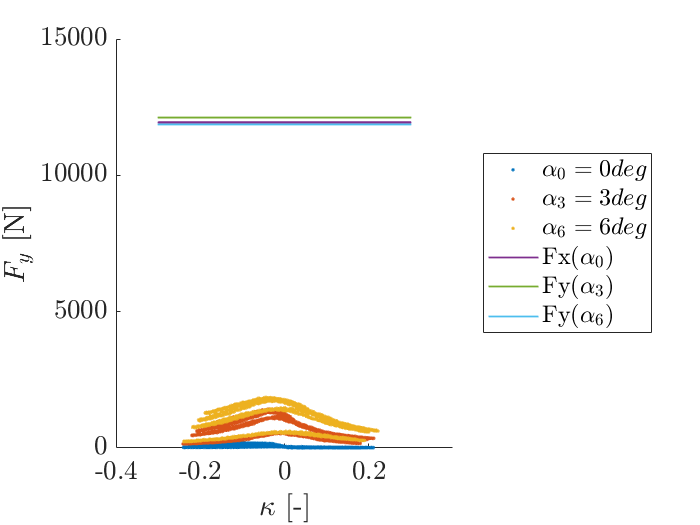


% Change tyre data with new optimal values                             
    tyre_coeffs_pl.rVy2 = P_opt_FY_dFz(1);  
 
% Check residuals!

[FY_comb_dFz_vec,~] = MF96_FY_vec(KAPPA_vec_y_comb_dFz, ALPHA_vec_y_comb_dFz, zeros_vec_y_comb_dFz, tyre_coeffs_pl.FZ0*ones_vec_y_comb_dFz, tyre_coeffs_pl);


tmp_zeros_comb_dFz = zeros(size(SL_vec));
tmp_ones_comb_dFz = ones(size(SL_vec));

[FY_dFz_var_vec1, Gxa_dFz_var_vec1] = MF96_FY_vec(SL_vec, mean(ALPHA_0_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(ALPHA_0_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz_var_vec2, Gxa_dFz_var_vec2] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(ALPHA_3_y_comb_dFz.FZ)*tmp_ones_comb_dFz,tyre_coeffs_pl);
[FY_dFz_var_vec3, Gxa_dFz_var_vec3] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(ALPHA_6_y_comb_dFz.FZ)*tmp_ones_comb_dFz,tyre_coeffs_pl);


figure('Name','FY(Fz) for all side slip angles','NumberTitle', 7 + last_fig_FX)
hold on
plot(ALPHA_0_y_comb_dFz.SL,ALPHA_0_y_comb_dFz.FY,'.','MarkerSize',5) %'MarkerEdgeColor','y',
plot(ALPHA_3_y_comb_dFz.SL,ALPHA_3_y_comb_dFz.FY,'.','MarkerSize',5) %'MarkerEdgeColor','c',
plot(ALPHA_6_y_comb_dFz.SL,ALPHA_6_y_comb_dFz.FY,'.','MarkerSize',5) %'MarkerEdgeColor','m',
plot(SL_vec,FY_dFz_var_vec1,'-s','LineWidth',1,'MarkerSize',1)
plot(SL_vec,FY_dFz_var_vec2,'-s','LineWidth',1,'MarkerSize',1)
plot(SL_vec,FY_dFz_var_vec3,'-s','LineWidth',1,'MarkerSize',1)
legend({'$ \alpha_0 = 0 deg $','$ \alpha_3 = 3 deg $','$ \alpha_6 = 6 deg $', 'Fx($\alpha_0$)','Fy($\alpha_3$)','Fy($\alpha_6$)'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{y}$ [N]')

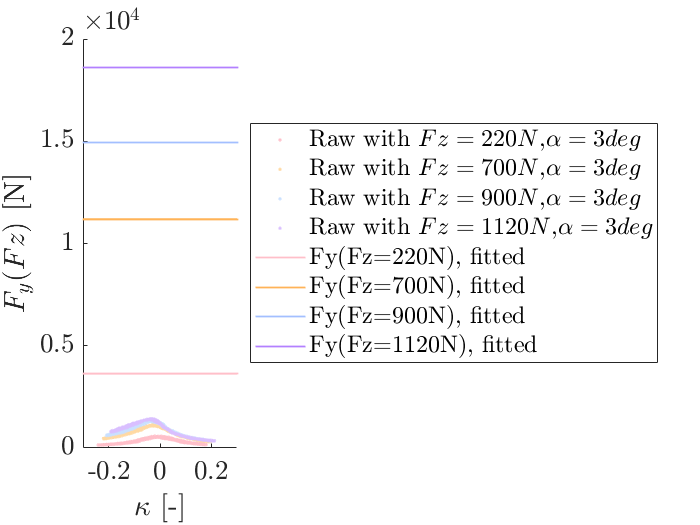



[FY_dFz220_alpha3_vec, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_220_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz700_alpha3_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_700_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz900_alpha3_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_900_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz1120_alpha3_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_1120_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);

figure('Name','FY(Fz) with alpha = 3 deg','NumberTitle', 8 + last_fig_FX)
hold on
plot(alpha3_FZ_220_y_comb_dFz.SL,alpha3_FZ_220_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[1 0.75 0.79]) %'MarkerEdgeColor','m',
plot(alpha3_FZ_700_y_comb_dFz.SL,alpha3_FZ_700_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[1 0.85 0.64]) %'MarkerEdgeColor','m',
plot(alpha3_FZ_900_y_comb_dFz.SL,alpha3_FZ_900_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[0.79 0.88 1]) %'MarkerEdgeColor','m',
plot(alpha3_FZ_1120_y_comb_dFz.SL,alpha3_FZ_1120_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[0.85 0.75 1]) %'MarkerEdgeColor','m',
plot(SL_vec,FY_dFz220_alpha3_vec,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 0.75 0.79])
plot(SL_vec,FY_dFz700_alpha3_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 0.7 0.34])
plot(SL_vec,FY_dFz900_alpha3_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[0.64 0.75 1])
plot(SL_vec,FY_dFz1120_alpha3_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[0.7 0.5 1])
legend({'Raw with $Fz=220N$,$\alpha=3 deg$','Raw with $Fz=700N$,$\alpha=3 deg$','Raw with $Fz=900N$,$\alpha=3 deg$','Raw with $Fz=1120N$,$\alpha=3 deg$','Fy(Fz=220N), fitted','Fy(Fz=700N), fitted', 'Fy(Fz=900N), fitted','Fy(Fz=1120N), fitted'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{y}(Fz)$ [N]')

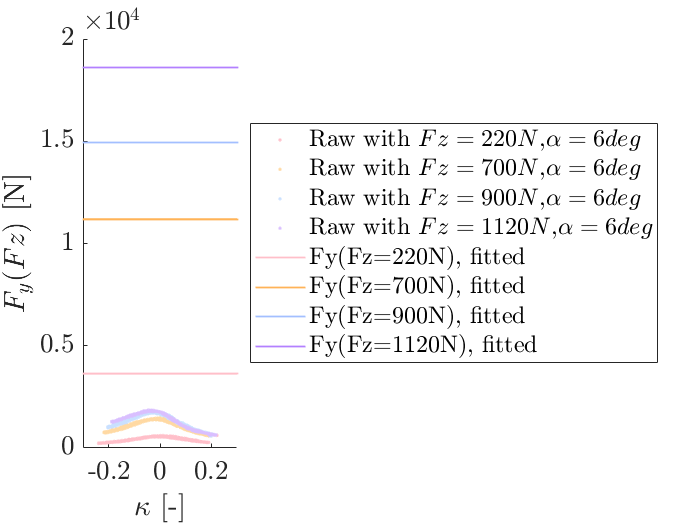


[FY_dFz220_alpha6_vec, Gxa_dFz220_var_vec1] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_220_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz700_alpha6_vec1, Gxa_dFz700_var_vec1] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_700_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz900_alpha6_vec1, Gxa_dFz900_var_vec1] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_900_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);
[FY_dFz1120_alpha6_vec1, Gxa_dFz1120_var_vec1] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dFz.SA)*tmp_ones_comb_dFz , tmp_zeros_comb_dFz, mean(FZ_1120_y_comb_dFz.FZ)*tmp_ones_comb_dFz, tyre_coeffs_pl);

figure('Name','FY(Fz) with alpha = 6 deg','NumberTitle', 9 + last_fig_FX)
hold on
plot(alpha6_FZ_220_y_comb_dFz.SL,alpha6_FZ_220_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[1 0.75 0.79]) %'MarkerEdgeColor','m',
plot(alpha6_FZ_700_y_comb_dFz.SL,alpha6_FZ_700_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[1 0.85 0.64]) %'MarkerEdgeColor','m',
plot(alpha6_FZ_900_y_comb_dFz.SL,alpha6_FZ_900_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[0.79 0.88 1]) %'MarkerEdgeColor','m',
plot(alpha6_FZ_1120_y_comb_dFz.SL,alpha6_FZ_1120_y_comb_dFz.FY,'.','MarkerSize',5,'Color',[0.85 0.75 1]) %'MarkerEdgeColor','m',
plot(SL_vec,FY_dFz220_alpha6_vec,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 0.75 0.79])
plot(SL_vec,FY_dFz700_alpha6_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 0.7 0.34])
plot(SL_vec,FY_dFz900_alpha6_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[0.64 0.75 1])
plot(SL_vec,FY_dFz1120_alpha6_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[0.7 0.5 1])
legend({'Raw with $Fz=220N$,$\alpha=6 deg$','Raw with $Fz=700N$,$\alpha=6 deg$','Raw with $Fz=900N$,$\alpha=6 deg$','Raw with $Fz=1120N$,$\alpha=6 deg$','Fy(Fz=220N), fitted','Fy(Fz=700N), fitted', 'Fy(Fz=900N), fitted','Fy(Fz=1120N), fitted'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{y}(Fz)$ [N]')

## ---FY(gamma): fitting with variable camber (gamma)

evaluate the differences at the same nominal load Fz = 220N

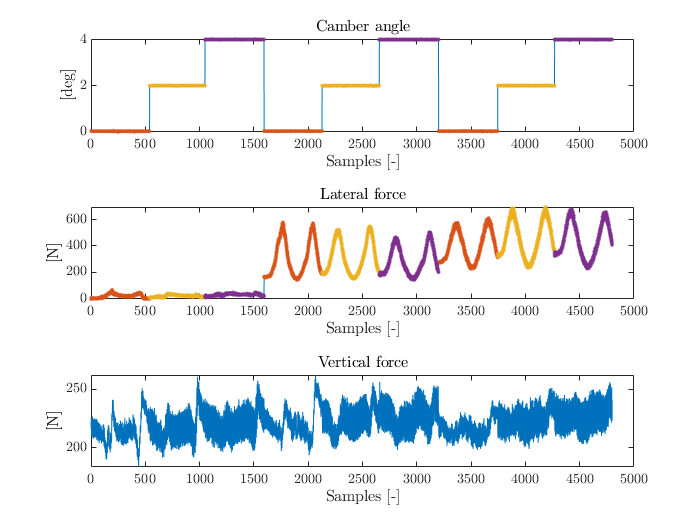

TData_y_comb_dgamma = FZ_220_comb;

smpl_range_y_comb_dgamma = size(TData_y_comb_dgamma);
vec_samples_y_comb_dgamma = 1:1:smpl_range_y_comb_dgamma;

% Extract points at constant side slip and plot
ALPHA_tol_y_comb_dgamma = 0.5*to_rad;
idx_y_comb_dgamma.ALPHA_0 = 0.0*to_rad-ALPHA_tol_y_comb_dgamma < TData_y_comb_dgamma.SA & TData_y_comb_dgamma.SA < 0.0*to_rad+ALPHA_tol_y_comb_dgamma;
idx_y_comb_dgamma.ALPHA_3 = 3.0*to_rad-ALPHA_tol_y_comb_dgamma < TData_y_comb_dgamma.SA & TData_y_comb_dgamma.SA < 3.0*to_rad+ALPHA_tol_y_comb_dgamma;
idx_y_comb_dgamma.ALPHA_6 = 6.0*to_rad-ALPHA_tol_y_comb_dgamma < TData_y_comb_dgamma.SA & TData_y_comb_dgamma.SA < 6.0*to_rad+ALPHA_tol_y_comb_dgamma;

ALPHA_0_y_comb_dgamma  = TData_y_comb_dgamma( idx_y_comb_dgamma.ALPHA_0, : );
ALPHA_3_y_comb_dgamma  = TData_y_comb_dgamma( idx_y_comb_dgamma.ALPHA_3, : );
ALPHA_6_y_comb_dgamma  = TData_y_comb_dgamma( idx_y_comb_dgamma.ALPHA_6, : );

% Extract points at constant camber and plot
GAMMA_tol_y_comb_dgamma = 0.05*to_rad;
idx_y_comb_dgamma.GAMMA_0 = 0.0*to_rad-GAMMA_tol_y_comb_dgamma < TData_y_comb_dgamma.IA & TData_y_comb_dgamma.IA < 0.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.GAMMA_1 = 2.0*to_rad-GAMMA_tol_y_comb_dgamma < TData_y_comb_dgamma.IA & TData_y_comb_dgamma.IA < 2.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.GAMMA_2 = 4.0*to_rad-GAMMA_tol_y_comb_dgamma < TData_y_comb_dgamma.IA & TData_y_comb_dgamma.IA < 4.0*to_rad+GAMMA_tol_y_comb_dgamma;

GAMMA_0_y_comb_dgamma  = TData_y_comb_dgamma( idx_y_comb_dgamma.GAMMA_0, : );
GAMMA_1_y_comb_dgamma  = TData_y_comb_dgamma( idx_y_comb_dgamma.GAMMA_1, : );
GAMMA_2_y_comb_dgamma  = TData_y_comb_dgamma( idx_y_comb_dgamma.GAMMA_2, : );

% Ranges for plot (Skip)
idx_y_comb_dgamma.alpha0_gamma0  = 0.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_0_y_comb_dgamma.IA & ALPHA_0_y_comb_dgamma.IA < 0.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.alpha0_gamma2  = 2.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_0_y_comb_dgamma.IA & ALPHA_0_y_comb_dgamma.IA < 2.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.alpha0_gamma4  = 4.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_0_y_comb_dgamma.IA & ALPHA_0_y_comb_dgamma.IA < 4.0*to_rad+GAMMA_tol_y_comb_dgamma;
alpha0_gamma0_y_comb_dgamma  = ALPHA_0_y_comb_dgamma( idx_y_comb_dgamma.alpha0_gamma0, : );
alpha0_gamma2_y_comb_dgamma  = ALPHA_0_y_comb_dgamma( idx_y_comb_dgamma.alpha0_gamma2, : );
alpha0_gamma4_y_comb_dgamma  = ALPHA_0_y_comb_dgamma( idx_y_comb_dgamma.alpha0_gamma4, : );

idx_y_comb_dgamma.alpha3_gamma0  = 0.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_3_y_comb_dgamma.IA & ALPHA_3_y_comb_dgamma.IA < 0.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.alpha3_gamma2  = 2.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_3_y_comb_dgamma.IA & ALPHA_3_y_comb_dgamma.IA < 2.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.alpha3_gamma4  = 4.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_3_y_comb_dgamma.IA & ALPHA_3_y_comb_dgamma.IA < 4.0*to_rad+GAMMA_tol_y_comb_dgamma;
alpha3_gamma0_y_comb_dgamma  = ALPHA_3_y_comb_dgamma( idx_y_comb_dgamma.alpha3_gamma0, : );
alpha3_gamma2_y_comb_dgamma  = ALPHA_3_y_comb_dgamma( idx_y_comb_dgamma.alpha3_gamma2, : );
alpha3_gamma4_y_comb_dgamma  = ALPHA_3_y_comb_dgamma( idx_y_comb_dgamma.alpha3_gamma4, : );

idx_y_comb_dgamma.alpha6_gamma0  = 0.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_6_y_comb_dgamma.IA & ALPHA_6_y_comb_dgamma.IA < 0.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.alpha6_gamma2  = 2.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_6_y_comb_dgamma.IA & ALPHA_6_y_comb_dgamma.IA < 2.0*to_rad+GAMMA_tol_y_comb_dgamma;
idx_y_comb_dgamma.alpha6_gamma4  = 4.0*to_rad-GAMMA_tol_y_comb_dgamma < ALPHA_6_y_comb_dgamma.IA & ALPHA_6_y_comb_dgamma.IA < 4.0*to_rad+GAMMA_tol_y_comb_dgamma;
alpha6_gamma0_y_comb_dgamma  = ALPHA_6_y_comb_dgamma( idx_y_comb_dgamma.alpha6_gamma0, : );
alpha6_gamma2_y_comb_dgamma  = ALPHA_6_y_comb_dgamma( idx_y_comb_dgamma.alpha6_gamma2, : );
alpha6_gamma4_y_comb_dgamma  = ALPHA_6_y_comb_dgamma( idx_y_comb_dgamma.alpha6_gamma4, : );

% Plot
figure('Name','FY(gamma): dataset with regions', 'NumberTitle', 10 + last_fig_FX)
tiledlayout(3,1)
ax_list_9(1) = nexttile;
plot(TData_y_comb_dgamma.IA*to_deg)
hold on
plot(vec_samples_y_comb_dgamma(idx_y_comb_dgamma.GAMMA_0),GAMMA_0_y_comb_dgamma.IA*to_deg,'.');
plot(vec_samples_y_comb_dgamma(idx_y_comb_dgamma.GAMMA_1),GAMMA_1_y_comb_dgamma.IA*to_deg,'.');
plot(vec_samples_y_comb_dgamma(idx_y_comb_dgamma.GAMMA_2),GAMMA_2_y_comb_dgamma.IA*to_deg,'.');
title('Camber angle')
xlabel('Samples [-]')
ylabel('[deg]')
hold off

ax_list_9(2) = nexttile;
plot(TData_y_comb_dgamma.FY)
hold on
plot(vec_samples_y_comb_dgamma(idx_y_comb_dgamma.GAMMA_0),GAMMA_0_y_comb_dgamma.FY,'.');
plot(vec_samples_y_comb_dgamma(idx_y_comb_dgamma.GAMMA_1),GAMMA_1_y_comb_dgamma.FY,'.');
plot(vec_samples_y_comb_dgamma(idx_y_comb_dgamma.GAMMA_2),GAMMA_2_y_comb_dgamma.FY,'.');
title('Lateral force')
xlabel('Samples [-]')
ylabel('[N]')
hold off

ax_list_9(3) = nexttile;
plot(TData_y_comb_dgamma.FZ)
title('Vertical force')
xlabel('Samples [-]')
ylabel('[N]')
linkaxes(ax_list_9,'x')


% Fit the coeffs {rVy3}

% Guess values for parameters to be optimised
%   [rVy3]
P0_FY_dgamma = [0];

% Limits for parameters to be optimised
lb_FY_dgamma = [ ];
ub_FY_dgamma = [ ];

zeros_vec_y_comb_dgamma = zeros(size(TData_y_comb_dgamma.IA));
ones_vec_y_comb_dgamma  = ones(size(TData_y_comb_dgamma.IA));

GAMMA_vec_y_comb_dgamma = TData_y_comb_dgamma.IA;
ALPHA_vec_y_comb_dgamma = TData_y_comb_dgamma.SA; 
KAPPA_vec_y_comb_dgamma = TData_y_comb_dgamma.SL; 
FY_vec_y_comb_dgamma    = TData_y_comb_dgamma.FY;
FZ_vec_y_comb_dgamma    = TData_y_comb_dgamma.FZ;


% Minimization of residuals
[P_FY_dgamma,fval_FY_dgamma,exitflag_FY_dgamma] = fmincon(@(P)resid_Fy_varGamma(P,FY_vec_y_comb_dgamma, KAPPA_vec_y_comb_dgamma, ALPHA_vec_y_comb_dgamma, GAMMA_vec_y_comb_dgamma,mean(FZ_vec_y_comb_dgamma)*ones_vec_y_comb_dgamma, tyre_coeffs_pl),...
                               P0_FY_dgamma,[],[],[],[],lb_FY_dgamma,ub_FY_dgamma);


Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


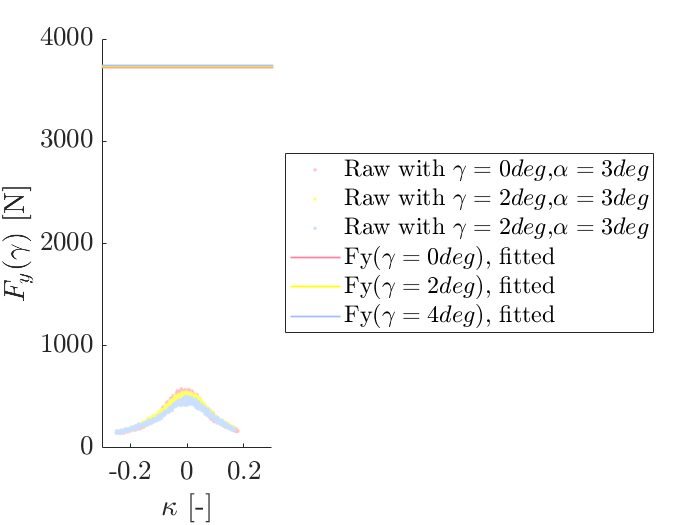


% Change tyre data with new optimal values                             
tyre_coeffs_pl.rVy3 = P_FY_dgamma(1);  

% Check residuals!

tmp_zeros_comb_dgamma = zeros(size(SL_vec));
tmp_ones_comb_dgamma = ones(size(SL_vec));


[FY_dgamma0_alpha3_var_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dgamma.SA)*tmp_ones_comb_dgamma , mean(GAMMA_0_y_comb_dgamma.IA)*tmp_ones_comb_dgamma, mean(ALPHA_3_y_comb_dgamma.FZ)*tmp_ones_comb_dgamma, tyre_coeffs_pl);
[FY_dgamma1_alpha3_var_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dgamma.SA)*tmp_ones_comb_dgamma , mean(GAMMA_1_y_comb_dgamma.IA)*tmp_ones_comb_dgamma, mean(ALPHA_3_y_comb_dgamma.FZ)*tmp_ones_comb_dgamma, tyre_coeffs_pl);
[FY_dgamma2_alpha3_var_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_3_y_comb_dgamma.SA)*tmp_ones_comb_dgamma , mean(GAMMA_2_y_comb_dgamma.IA)*tmp_ones_comb_dgamma, mean(ALPHA_3_y_comb_dgamma.FZ)*tmp_ones_comb_dgamma, tyre_coeffs_pl);

figure('Name','FY(gamma) with alpha = 3deg','NumberTitle', 11 + last_fig_FX)
hold on
plot(alpha3_gamma0_y_comb_dgamma.SL,alpha3_gamma0_y_comb_dgamma.FY,'.','MarkerSize',5,'Color',[1 0.75 0.79])
plot(alpha3_gamma2_y_comb_dgamma.SL,alpha3_gamma2_y_comb_dgamma.FY,'.','MarkerSize',5,'Color',[1 1 0.4])
plot(alpha3_gamma4_y_comb_dgamma.SL,alpha3_gamma4_y_comb_dgamma.FY,'.','MarkerSize',5,'Color',[0.79 0.88 1])
plot(SL_vec,FY_dgamma0_alpha3_var_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 0.5 0.64])
plot(SL_vec,FY_dgamma1_alpha3_var_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 1 0])
plot(SL_vec,FY_dgamma2_alpha3_var_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[0.64 0.75 1])
legend({'Raw with $\gamma=0deg$,$\alpha=3 deg$','Raw with $\gamma=2deg$,$\alpha=3 deg$','Raw with $\gamma=2deg$,$\alpha=3 deg$','Fy($\gamma=0deg$), fitted','Fy($\gamma=2deg$), fitted', 'Fy($\gamma=4deg$), fitted'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{y}(\gamma)$ [N]')

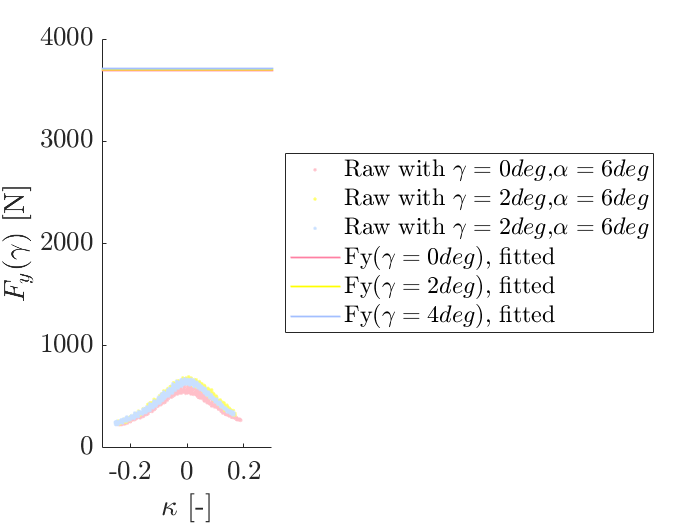


[FY_dgamma0_alpha6_var_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dgamma.SA)*tmp_ones_comb_dgamma , mean(GAMMA_0_y_comb_dgamma.IA)*tmp_ones_comb_dgamma, mean(ALPHA_6_y_comb_dgamma.FZ)*tmp_ones_comb_dgamma, tyre_coeffs_pl);
[FY_dgamma1_alpha6_var_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dgamma.SA)*tmp_ones_comb_dgamma , mean(GAMMA_1_y_comb_dgamma.IA)*tmp_ones_comb_dgamma, mean(ALPHA_6_y_comb_dgamma.FZ)*tmp_ones_comb_dgamma, tyre_coeffs_pl);
[FY_dgamma2_alpha6_var_vec1, ~] = MF96_FY_vec(SL_vec, mean(ALPHA_6_y_comb_dgamma.SA)*tmp_ones_comb_dgamma , mean(GAMMA_2_y_comb_dgamma.IA)*tmp_ones_comb_dgamma, mean(ALPHA_6_y_comb_dgamma.FZ)*tmp_ones_comb_dgamma, tyre_coeffs_pl);

figure('Name','FY(gamma) with alpha = 6deg','NumberTitle', 12 + last_fig_FX)
hold on
plot(alpha6_gamma0_y_comb_dgamma.SL,alpha6_gamma0_y_comb_dgamma.FY,'.','MarkerSize',5,'Color',[1 0.75 0.79])
plot(alpha6_gamma2_y_comb_dgamma.SL,alpha6_gamma2_y_comb_dgamma.FY,'.','MarkerSize',5,'Color',[1 1 0.4])
plot(alpha6_gamma4_y_comb_dgamma.SL,alpha6_gamma4_y_comb_dgamma.FY,'.','MarkerSize',5,'Color',[0.79 0.88 1])
plot(SL_vec,FY_dgamma0_alpha6_var_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 0.5 0.64])
plot(SL_vec,FY_dgamma1_alpha6_var_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[1 1 0])
plot(SL_vec,FY_dgamma2_alpha6_var_vec1,'-s','LineWidth',1,'MarkerSize',1,'Color',[0.64 0.75 1])
legend({'Raw with $\gamma=0deg$,$\alpha=6 deg$','Raw with $\gamma=2deg$,$\alpha=6 deg$','Raw with $\gamma=2deg$,$\alpha=6 deg$','Fy($\gamma=0deg$), fitted','Fy($\gamma=2deg$), fitted', 'Fy($\gamma=4deg$), fitted'}, 'Location','eastoutside');
xlabel('$\kappa$ [-]')
ylabel('$F_{y}(\gamma)$ [N]')